** Федеральное агентство железнодорожного транспорта**

Федеральное государственное бюджетное образовательное учреждение

высшего образования

«**Петербургский** **государственный университет путей сообщения Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

­­­­­­­­­­­­––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––

Факультет «Транспортные и энергетические системы» 

Кафедра «Электрическая тяга»

**ОТЧЁТ**

**по лабораторной работе №6**

**«**Исследование трехфазного (мостового) автономного инвертора напряжения**»**

**Вариант №4**

Выполнили:

студенты гр. ПС-003 

Дулепов И.Г.

Минина А.С.

Проверил:

Сычугов А.Н.

Санкт-Петербург

2024

**1. Цель работы** - Исследование методом компьютерного моделирования трехфазного (мостового) автономного инвертора с симметричным управлением и синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку. 

**2. Карткие теоретические сведения:**

Трехфазный автономный инвертор напряжения – устройство, предна значенное для преобразования постоянного тока в переменный ток с возмож ностью управления частотой и амплитудой выходного сигнала.  

В настоящее время в системе электроснабжения железных дорог пере менного тока и метрополитенов используется асинхронный тяговый электро привод, одним из основных элементов которого является мостовой автоном ный инвертор.  

Силовая часть трехфазного автономного инвертора напряжения содер жит шесть транзисторных ключей VT1–VT6 с шестью диодами обратного  тока VD1–VD6, образующих мостовую схему и присоединенных параллель но к источнику питания. Упрощенная схема трехфазного мостового АИН с  использованием IGBT-транзисторов изображена на рисунке 1.

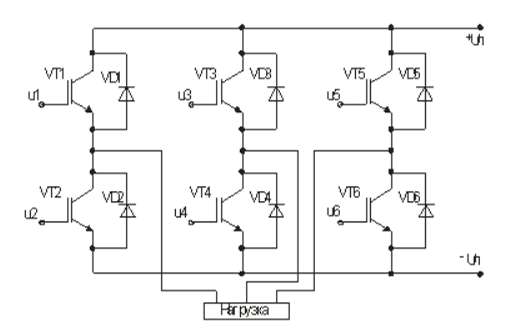

Рисунок 1 – Упрощенная схема трехфазного мостового АИН с использованием IGBT-транзисторов.

Длительность переключения транзисторных ключей и, следовательно,  частота выходного напряжения определяется системой управления. На ин тервале одного периода выходного напряжения транзисторы анодной и ка тодной групп могут переключаться однократно и многократно. При одно кратном переключении транзисторы могут находиться в открытом состоянии  в течение 120, 150 или 180° эл. Простейшим способом управления транзи сторными ключами VT1–VT6 инвертора, обеспечивающим неизменность  структуры силовой цепи, является способ с a = 180° эл. Простейшими спосо бами управления транзисторами, при которых изменяется структура силовой  цепи инвертора, являются способы с a = 120° и a = 150° эл. При этих спосо бах управления в схеме выходного каскада образуются ветви, замыкающиеся  только через диоды обратного моста. Структура выходной цепи такого ин вертора будет зависеть от направления тока в этих ветвях. В свою очередь  момент изменения тока в той или иной ветви схемы зависит от характера  нагрузки. Поэтому форма выходного напряжения при a = 120° также будет  зависеть от характера нагрузки. При a = 120° структура силовой цепи остает ся неизменной, если cosφн ≤ 0,55. Форма напряжения на нагрузке в этом слу чае аналогична форме при a = 180°. Общим недостатком этих способов явля ется необходимость применения управляемых вентилей. Нагрузка трехфаз ного АИН включается либо по схеме звезды, либо по схеме треугольника.  

Эффективное значение фазного напряжения при соединении нагрузки звез дой определяется по формуле.

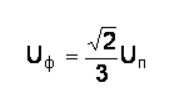

Где: Uп – напряжение источника питания.

Соответственно эффективное значение линейного напряжения равно:

Форма тока выходной цепи зависит от характера нагрузки. При актив но-индуктивной нагрузке она представляет собой ломанную кривую, состо ящую из четырех экспонент на участке, равном половине периода. Эффек тивное значение тока нагрузки определяется путем интегрирования харак терных участков кривой тока. 

При соединении нагрузки звездой действующее значение тока равно:

Где: к - коэффициент, обратно пропорциональный постоянной времени

Выражение справедливо для промежутка времени: 

Требуемую форму тока нагрузки, в том числе и синусоидальную, мож но получить путем многократного включения и отключения управляемых  вентилей на интервале одного периода. При этом плавно изменяется эффек тивное значение напряжения на нагрузке.  

Для регулирования выходного напряжения с помощью инвертора  наибольшее применение находит широтно-импульсная модуляция (ШИМ) с  формированием огибающей в виде прямоугольника, трапеции или синусои ды. Прямоугольную модуляцию иначе называют широтно-импульсным регу лированием (ШИР). Широтно-импульсное регулирование напряжения на вы ходе инвертора на основной частоте осуществляется изменением относи тельной продолжительности включения нагрузки в цепь источника питания.  Находит применение ШИР, когда в паузе между импульсами запираются два  силовых транзистора одной группы. Тогда при открытых транзисторах VT1,  VT2, VT3 для создания паузы в напряжении на нагрузке запираются VT1 и  VT3. Алгоритм одиночного переключения способен формировать паузу в  выходном напряжении инвертора при любых значениях постоянной времени

При алгоритме группового переключения создается пауза в напряже нии на нагрузке, если к моменту запирания двух транзисторов группы ток  изменит знак. Это явление может быть при небольших значениях постоян ных времени нагрузки. Если значение велико и к рассматриваемому моменту  ток не изменит знака, то паузу в выходном напряжении сформировать не  удастся. При ШИР на основной частоте гармонический состав выходного  напряжения и тока резко ухудшается в области малых напряжений и частот.  Для исключения этого нежелательного явления используется широтно импульсное регулирование на несущей частоте. Наибольшее снижение со держания высших гармоник достигается при широтно-импульсной модуля ции по синусоидальному закону. При этом в схеме управления формируется  опорное напряжение треугольной формы, которое сравнивается с модулиру ющей кривой синусоидальной формы. Длительность импульса выходного  напряжения определяется точками пересечения этих кривых.

**3. Схема виртуальной установки:**

Виртуальная лабораторная установка для исследований, приведена на рисунке 2.

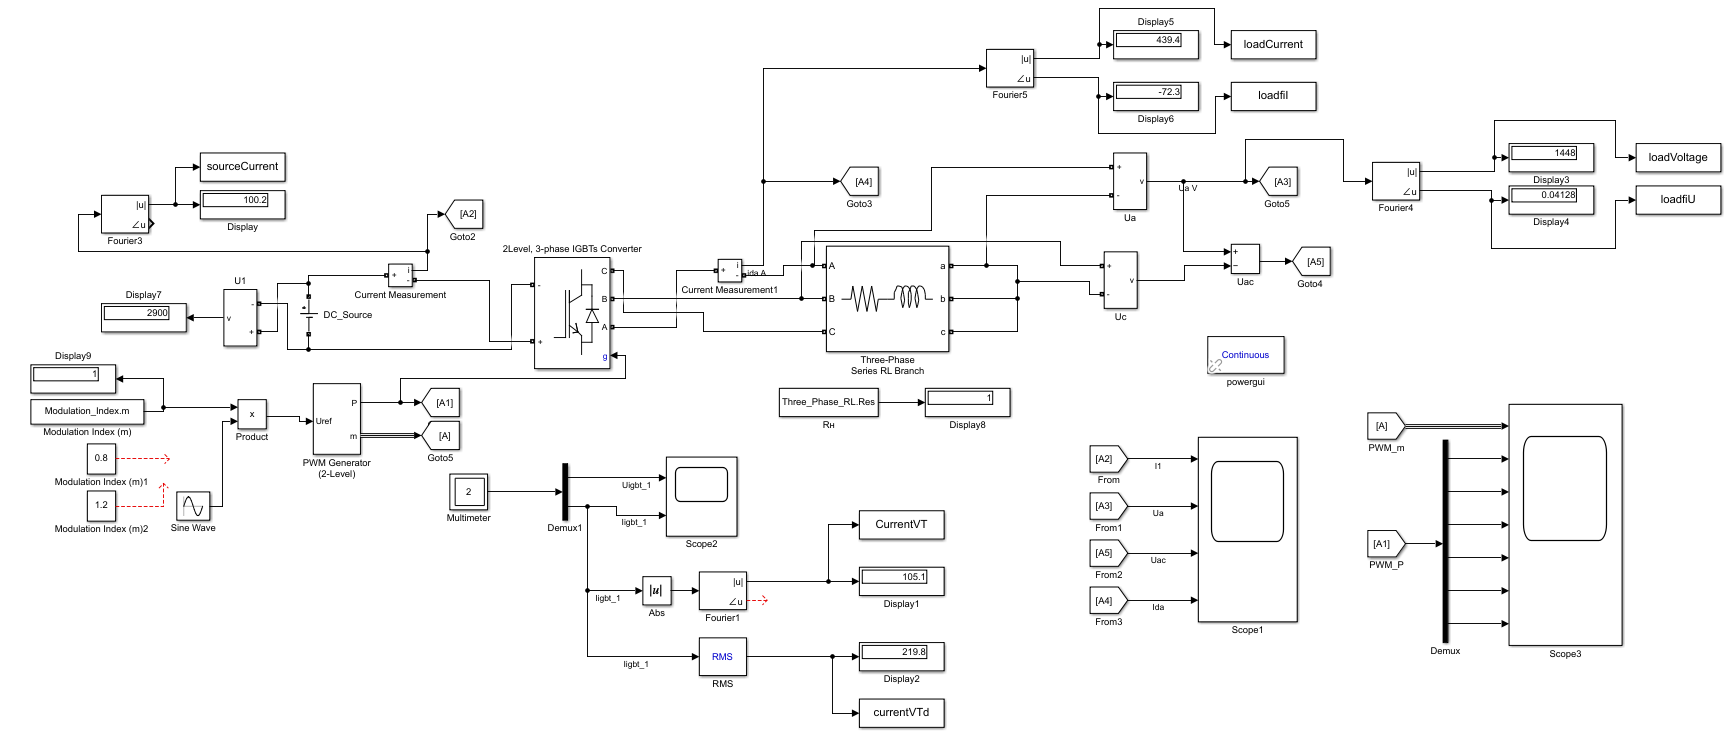

Рисунок 2. Компьютерная модель трехфазного автономного инвертора напряжения в Simulink

Данная лабораторная установка содержит следующие блоки:

- Блок «DC», моделирующий источник постоянного напряжения; 

- Блоки «RL», моделирующие сопротивление и индуктивность ис точника питания, а также нагрузки соответственно;

- Блок «IGBT», моделирующий IGBT инвертер;

- Блоки для передачи сигналов «GoTo1» и «From1», в параметрах  блоков указывается имя переменной, посредством которой осу ществляется обмен данными;

- «PWM Generator (2-Level)», формирует на выходе импульсы  управления выпрямителем;

- Блок «Uref Generation» задает параметры моделирующего напря жения, частоту и начальные фазы системы 3х фазного напряже ния;

- Блок «Fourier» применяется для измерения гармонических со ставляющих;

- Блок «RMS1» применяется для измерения действующего тока в  транзисторе;

- Блок «ToWorkspace» применяется вывода результатов измерений  в рабочую область Matlab;

- «Scope1-Scope3» – осциллографы.  

**4. Содержание работы:**

4.1. Исследование внешних и энергетических характеристик трехфазного  (мостового) автономного инвертора с симметричным управлением, с синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку.  

4.2. Исследование регулировочной характеристики трехфазного (мостового)  автономного инвертора с симметричным управлением, с синусоидальной широтно-импульсной модуляцией при работе на активно-индуктивную  нагрузку.  

4.3. Исследование гармонического состава напряжения и тока на нагрузке трехфазного (мостового) автономного инвертора с симметричным управлением,  с синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку. 

**5. Задание исходных данных:**

Открываем файл с заданными параметрами:

open('Исходные данные к ЛР6.txt')

Используем исходные данные, импортируемые из текстового файла задания:

C = readcell('Исходные данные к ЛР6.txt');
ishoddan = C(1:16, 1:3);
data.Var = ishoddan{3,3};
data.Udc = ishoddan{5,3};
data.Ufd = ishoddan{7,3};
data.Uf = ishoddan{8,3};
data.Ron = ishoddan{9,3};
data.f0 = ishoddan{11,3};
data.N = ishoddan{13,3};
data.m1 = ishoddan{15,3};
data.m2 = ishoddan{16,3};
data.T = table(data.Var.',data.Udc.', data.Ufd.', data.Uf.', data.Ron.', data.f0.', data.N.', data.m1.', data.m2.');
data.T.Properties.VariableNames = ["Вариант №", "Udc, В","Ufd, В","Uf,В", "Ron, Ом","f0, Гц","N=fn/f0", "m1", "m2"];
disp(data.T);

    Вариант №    Udc, В    Ufd, В    Uf,В    Ron, Ом    f0, Гц    N=fn/f0    m1     m2 
    _________    ______    ______    ____    _______    ______    _______    ___    ___

        4         2900      1.2      1.2     0.0025      250        17       0.8    1.2



**Далее задаем в блоки модели Simulink:**

**Параметры источника питания:**

В поле настройки блока "DC" задаем величину постоянного напряжения, В.:

DC_Source.Voltage = data.Udc;

**Параметры нагрузки:**

В поле настройки блока "Three-Phase Series RL Branch" задаем величины активного сопротивления и индуктивности нагрузки:

Активное сопротивление Rн изменяется в пределах от 1 до 10 Ом.:

Three_Phase_RL.Res = 1; % значение активного сопротивления (для первого опыта принимаем Rн = 1), Ом.

Индуктивность нагрузки вычисляем по формуле Lн=0,5Rн/f0. 

Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5; % значение индуктивности на нагрузке, Гн.

**Параметры трехфазного (мостового) транзисторного модуля:**

В поле настройки блока "2Level, 3-phase IGBTs Converter" (моделирующий IGBT инвертор) задаем:

phase_3_IGBTs.SnubberRs = 1e6; %параметры демпфирующих цепей (Snubber resistance, Snubber capacitance)
phase_3_IGBTs.SnubberCs = inf;
phase_3_IGBTs.R_on = data.Ron; %динамическое сопротивление полупроводникового модуля открытом состоянии в Омах (Ron, Ом.)
phase_3_IGBTs.Vf = data.Uf; %пороговое напряжение на транзисторе и диоде модуля в открытом состоянии в вольтах, В.
phase_3_IGBTs.Vfd = data.Ufd;

**Параметры блоков для передачи сигналов GoTo и From:**

В параметрах блоков  указывается имя переменной, посредством которой осуществляется обмен данными.

**Параметры блока формирования импульсов для управления преобразователем:**

В поле настройки блока "PWM Generator (2-Level)" задаем:

PWM_generator.frec = data.f0*20; %несущая частота пилообразного напряжения, Гц.

Остальные параметры блока PWM остаются без имененений.

**Параметры блока "Sine Wave" (Генератор непрерывной синусоидальной волны):**

В окне параметров блока Sine Wave вводим параметры моделирующего напряжения, угловой частоты (f=2*π*f0 Гц.) и начальных фаз системы 3х-фазного напряжения в виде массива данных ([0 -2*pi/3 2*pi/3]):

Sine_Wave.amplitude = 1; %амплитуда модулирующего напряжения, В.
Sine_Wave.freq = 2*pi*data.f0; % угловая частота модулирующего напряжения, рад/c.
Sine_Wave.Phase = [0 -2*pi/3 2*pi/3];  % начальные фазы 3х-фазного модулирующего напряжения, рад.

**Параметры блока Fourier 3:**

В полях настройки устанавливаем частоту равную частоте моделирующего сигнала f0 и номер нулевой гармоники:

Fourier_3.frec = data.f0;
Fourier_3.harmonic = 0;

**Параметры блоков Fourier 1, Fourier 4 и Fourier 5:**

В полях настройки устанавливаем частоту равную частоте моделирующего сигнала f0 и номер первой гармоники:

Fourier_1_4_5.frec = data.f0;
Fourier_1_4_5.harmonic = 1;

**Параметры блока RMS 1 (блока измерения действующего тока в полупроводниковом модуле):**

В полях настройки устанавливаем частоту равную частоте моделирующего сигнала f0:

RMS_T.frec = data.f0; %частота моделирующего сигнала, Гц.

**Параметры блока "Modulation Index (m)" (коэффициента модуляции напряжения на нагрузке):**

В поле настройки задаем блока задаем величину коэффициента модуляции напряжения на нагрузке:

m0 = 1;
Modulation_Index.m = m0;

**6. Таблицы опытных и расчетных данных.**

**6.1. Исследование внешних и энергетических характеристик трехфазного  (мостового) автономного инвертора с симметричным управление, с синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку:**

Моделирование проводим для каждого значения сопротивления нагрузки Rн.  Результаты моделирования заносим в таблицу 1.

Подготавливаем массивы для снятия параметров измерений в таблицу 1.

%Данные
R_n = []; %Ом.
L_n = []; %Гн.
%Измерения
I1 = []; %А.
U_n1 = []; %В.
fi_U = []; %град.
I_n1 = []; %А.
fi_I = []; %град.
I_T0 = []; %А.
I_T_RMS = []; %А.
%Вычисления
fi_n1 = []; %град.
S_n1 = []; %ВА.
P_n1 = []; %Вт.
P_T = []; %Вт.
P_1 = []; %Вт.

Открываем файл исследуемой модели:

open('SHEST.slx')

При снятии характеристик актвное сопротивление на нагрузке Rн изменяем в пределах от 1 до 10 Ом.:

Задаем шаг с которым будет изменятся значение сопротивления Rн: 

RnStep = 1; %значение шага Rн.
Rnmin = 1; %начальное значение Rн.
Rnmax = 10; %конечное значение Rн.
RnnumStep=round((Rnmax-Rnmin)/RnStep+1) %количество шагов Rн.

RnnumStep = 10

Производим снятие характеристик:

for R = Rnmin:RnStep:Rnmax
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    sim('SHEST');
    R_n(end+1) = Three_Phase_RL.Res(end, 1);
    L_n(end+1) = round(Three_Phase_RL.Ind(end, 1),4);
    I1(end+1) = round(max(sourceCurrent(end, 1)),3);
    U_n1(end+1) = round(max(loadVoltage(end, 1)),2);
    fi_U(end+1) = round(max(loadfiU(end, 1)),4);
    I_n1(end+1) = round(max(loadCurrent(end, 1)),2);
    fi_I(end+1) = round(max(loadfiI(end, 1)),2);
    I_T0(end+1) = round(max(CurrentVT(end, 1)),3);
    I_T_RMS(end+1) = round(max(currentVTd(end, 1)),3);
    fi_n1(end+1) = (round(max(loadfiU(end, 1)),3)) - (round(max(loadfiI(end, 1)),3));
    S_n1(end+1) = round((3*(round(max(loadVoltage(end, 1)),2)) * (round(max(loadCurrent(end, 1)),2)))/2,2);
    P_n1(end+1) = round((3*(round(max(loadVoltage(end, 1)),2)) * (round(max(loadCurrent(end, 1)),2))*cos(deg2rad((round(max(loadfiU(end, 1)),3)) - (round(max(loadfiI(end, 1)),3)))))/2,2);
    P_T(end+1) = (Modulation_Index.m*phase_3_IGBTs.Vf+(1-Modulation_Index.m)*phase_3_IGBTs.Vfd*((cos(deg2rad((round(max(loadfiU(end, 1)),3)) - (round(max(loadfiI(end, 1)),3))))-1)/(cos(deg2rad((round(max(loadfiU(end, 1)),3)) - (round(max(loadfiI(end, 1)),3))))+1)))*round(max(CurrentVT(end, 1)),3)+phase_3_IGBTs.R_on*((round(max(currentVTd(end, 1)),3))^2);
    P_1(end+1) = round(DC_Source.Voltage*(round(max(sourceCurrent(end, 1)),3)),2);
end

Результаты моделирования и последующих вычислений заносим в таблицу 1.

Таблица 1 – Таблица измерений и вычислений

T1 = table(R_n.',L_n.',I1.',U_n1.',fi_U.',I_n1.',fi_I.',I_T0.',I_T_RMS.',fi_n1.',S_n1.', P_n1.',P_T.', P_1.');
T1.Properties.VariableNames = ["R_n, Ом.", "L_n, Гн.", "I1, А.", "U_n1, В.", "fi_U, град", "I_n1, А.", "fi_I, град.", "I_T0, А.", "I_T_RMS, А.", "fi_n1, град.", "S_n1, ВА.", "P_n1, Вт.", "P_T, Вт.", "P_1, Вт."];
disp(T1);

    R_n, Ом.    L_n, Гн.    I1, А.    U_n1, В.    fi_U, град    I_n1, А.    fi_I, град.    I_T0, А.    I_T_RMS, А.    fi_n1, град.    S_n1, ВА.     P_n1, Вт.     P_T, Вт.     P_1, Вт. 
    ________    ________    ______    ________    __________    ________    ___________    ________    ___________    ____________    __________    __________    ________    __________

        1        0.002      100.23     1448.3       0.0413       439.42        -72.3        105.14       219.79          72.345        9.546e+05    2.895

Пример расчета величин для строки 4 (Rн = 4 Ом):

Сдвиг по фазе между первой гармоникой тока и напряжения на нагрузке  рассчитываем по формуле:

fi_n14 = fi_U(4) - fi_I(4)

fi_n14 = 72.3402

Полную и активную мощности по первой гармонике в нагрузке определяем по выражениям:

 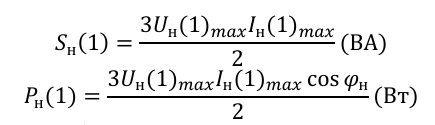

S_n14 = round((3*(U_n1(4)) * (I_n1(4)))/2,2)

S_n14 = 2.3872e+05

P_n14 = round((3*(U_n1(4)) * (I_n1(4)) * cos(deg2rad(fi_n1(4))))/2,2)

P_n14 = 7.2402e+04

Потери в силовом полупроводниковом модуле определяем по формуле:

P_T4 = round((Modulation_Index.m*phase_3_IGBTs.Vf+(1-Modulation_Index.m)*phase_3_IGBTs.Vfd*(((cos(deg2rad(fi_n14))-1)/(cos(deg2rad(fi_n14))+1))))*I_T0(4)+phase_3_IGBTs.R_on*((I_T_RMS(4))^2),3)

P_T4 = 39.0890

где Vf, Vfd, Ron – параметры силового модуля, Iто, IтRMS – его средний и  действующий ток.  Коэффициент модуляции m = U_мод/U_ГПН, где U_мод – амплитуда  моделирующего сигнала, U_ГПН – амплитуда напряжения ГПН. 

Мощность, потребляемую от источника питания, определяем по выражению:

P_14 = round(DC_Source.Voltage*(I1(4).'),2)

P_14 = 7.2575e+04

**6.2. Исследование регулировочной характеристики инвертора:**

Исследование регулировочной характеристики инвертора осуществляем на модели при одном значении сопротивления нагрузки Rн (Rн=1) и изменении величины коэффициента модуляции напряжения от 0 до 1 В с шагом 0,2 В.  Моделирование осуществляем при каждом значении модулирующего напряжения. Результаты моделирования заносим в таблицу 2.

Подготавливаем массивы для снятия параметров измерений в таблицу 2.

m_2 = [];
U_n2 = []; %В.

Задаем шаг с которым будет изменятся значение  коэффициента модуляции  m:

m_modStep= 0.2; %значение шага m
m_modmin= 0; %начальное значение m
m_modmax = 1; %конечное значение m
m_mod = (m_modmin:m_modStep:m_modmax).';
m_modStep=height(m_mod) %количество шагов m

m_modStep = 6

Производим снятие характеристик:

for mmod = m_mod(1:1:end).'
    Modulation_Index.m = mmod;
    Three_Phase_RL.Res = 1;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    sim('SHEST');
    m_2(end+1) = Modulation_Index.m(end, 1);
    U_n2(end+1) = round(max(loadVoltage(end, 1)),2);
end

Результаты моделирование для построении регулировочной характеристики представлены в таблице 2. 

Таблица 1 – Регулировочная характеристика инвертора

T2 = table(m_2.',U_n2.');
T2.Properties.VariableNames = ["m","Uн, В."];
disp(T2);

     m     Uн, В.
    ___    ______

      0         0
    0.2    289.73
    0.4     579.4
    0.6    869.01
    0.8    1158.7
      1    1448.3



**7. Нагрузочная характеристика инвертора. **

Нагрузочная характеристика зависимости напряжения от тока на нагрузке Uн = f(Iн) при изменении сопротивления Rн от 1 до 10 Ом. представлена ниже:

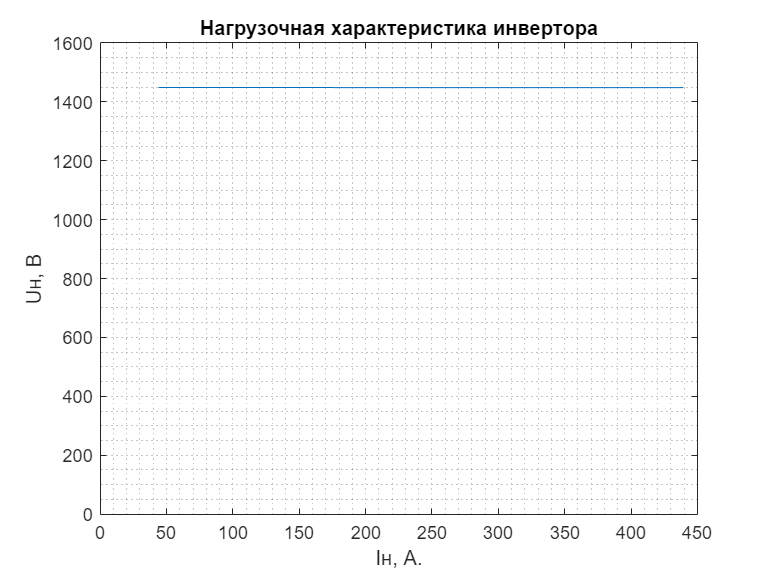

x1 = I_n1(1:10).';
y1 = U_n1(1:10).';
plot(x1,y1)
grid("minor");
xlabel('Iн, А.');
ylabel('Uн, В');
title('Нагрузочная характеристика инвертора');
ylim([0 1600]);

**8. Энергетические характеристики инвертора.  **

Энергетические характеристики зависимости тока питания, тока силового транзисторного модуля и действующего тока силового транзисторного модуля от тока нагрузки соответсвенно I1, IT0, IT(RMS) = f(Iн) представлены ниже:

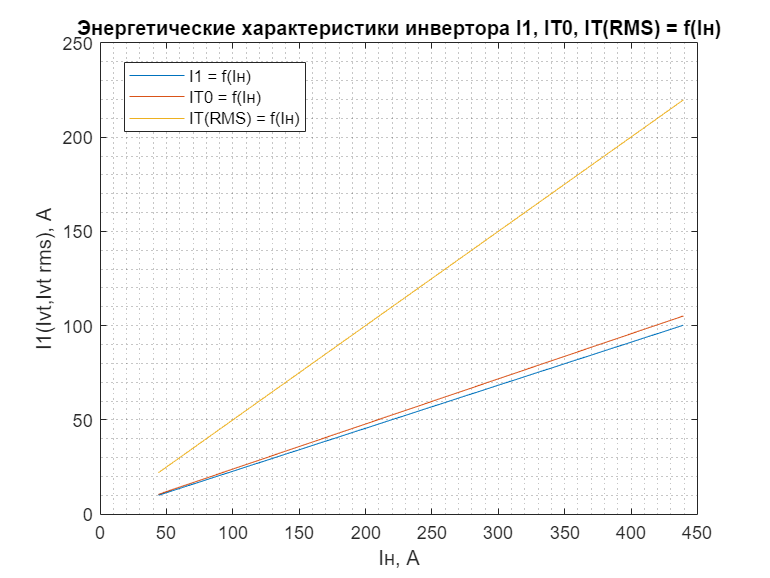

x1 = I_n1(1:10).';
y1 = I1(1:10).';
x2 = I_n1(1:10).';
y2 = I_T0(1:10).';
x3 = I_n1(1:10).';
y3 = I_T_RMS(1:10).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('I1(Ivt,Ivt rms), А');
title('Энергетические характеристики инвертора I1, IT0, IT(RMS) = f(Iн)');
legend(["I1 = f(Iн)","IT0 = f(Iн)","IT(RMS) = f(Iн)"])
legend("Position",[0.16134,0.77261,0.23571,0.11905])

Энергетические характеристики зависимости полной мощности и активной мощности по первой гармонике в нагрузке от мощности, потребляемой от источника питания Sн(1), Pн(1) = f(P1) представлены ниже:

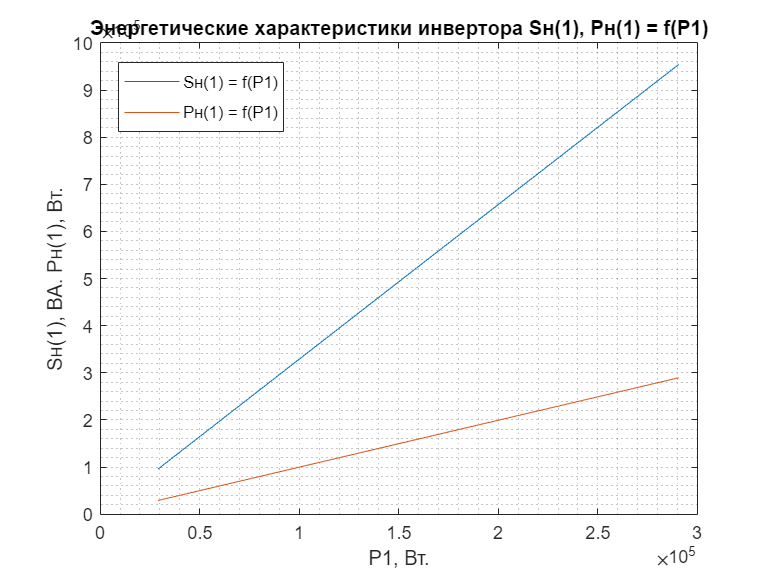

x1 = P_1(1:10).';
y1 = S_n1(1:10).';
x2 = P_1(1:10).';
y2 = P_n1(1:10).';
plot(x1,y1,x2,y2)
grid("minor");
xlabel('P1, Вт.');
ylabel('Sн(1), ВА. Pн(1), Вт.');
title('Энергетические характеристики инвертора Sн(1), Pн(1) = f(P1)');
legend(["Sн(1) = f(P1)","Pн(1) = f(P1)"])
legend("Position",[0.1542,0.77261,0.21429,0.11905])

Энергетическая характеристика зависимости потерь мощности в транзисторном модуле от мощности, потребляемой от источника питания Pт = f(P1) представлена ниже:

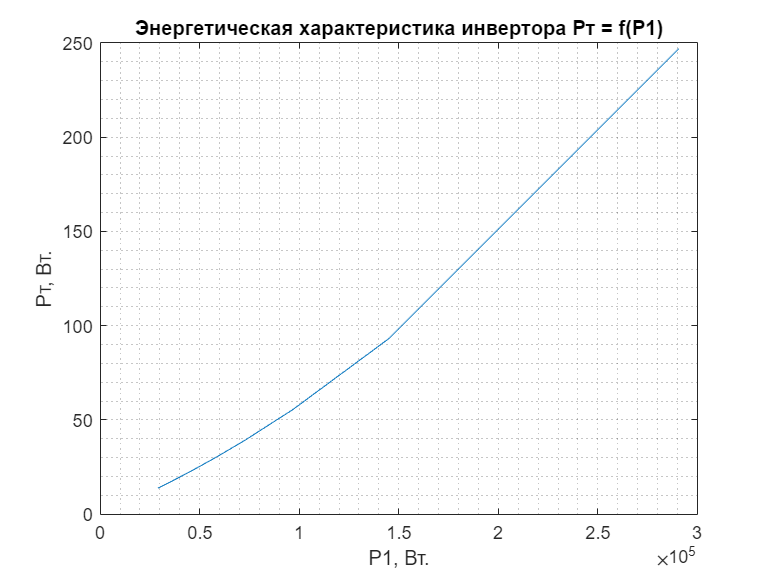

x1 = P_1(1:10).';
y1 = P_T(1:10).';
plot(x1,y1)
grid("minor");
xlabel('P1, Вт.');
ylabel('Pт, Вт.');
title('Энергетическая характеристика инвертора Pт = f(P1)');

**9. Регулировочная характеристика инвертора. **

Регулировочная характеристика зависимости амплитуды модулирующего напряжения от напряжения на нагрузке Uмод = f(Uн) представлена ниже:

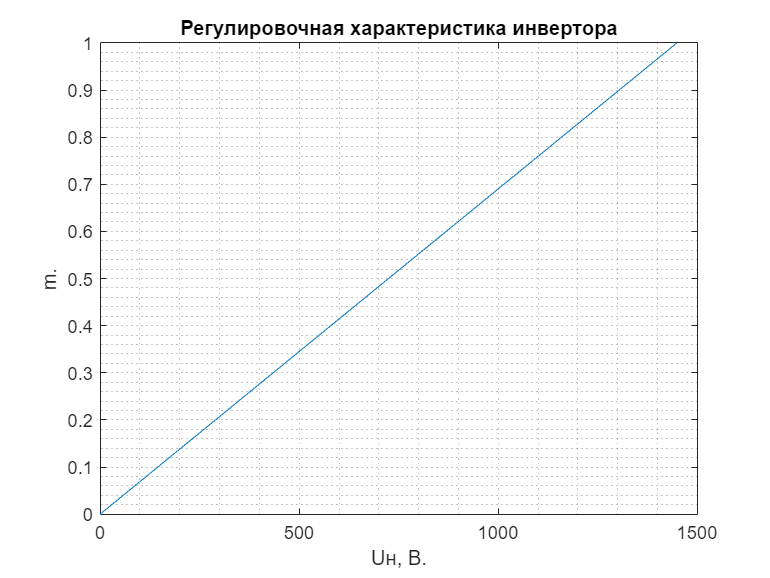

x1 = U_n2(1:6).';
y1 = m_2(1:6).';
plot(x1,y1)
grid("minor");
xlabel('Uн, В.');
ylabel('m.');
title('Регулировочная характеристика инвертора');

**10. Спектральный состав напряжения и тока нагрузки:**

Исследование спектрального состава напряжения и тока нагрузки инвертора осуществляем при двух значениях коэффициента модуляции m>1  и m<1 и при одном значении сопротивления нагрузки Rн (Rн=1).

Исследование проводим в ручном режиме. Для этого в блоке Powergui запускаем инструмент анализа  сигналов FFT Analysis. Далее выбираем в открывшемся окне FFT  Analyzer соответствующий сигнал (тока или напряжения). 

Задаем начальную точку исследования, при которой сигнал становится квазиустановившемся. Далее задаем число циклов исследований – не  менее 2, основная частота f0 модулирующего сигнала и максимальная частота  исследований - до 7-й гармоники. Проводим соответствующие исследования. 

Спектральный анализ напряжения и тока нагрузки для величины коэффициента модуляции напряжения m1 = 0,8 изображен на рисунках 3 и 4:

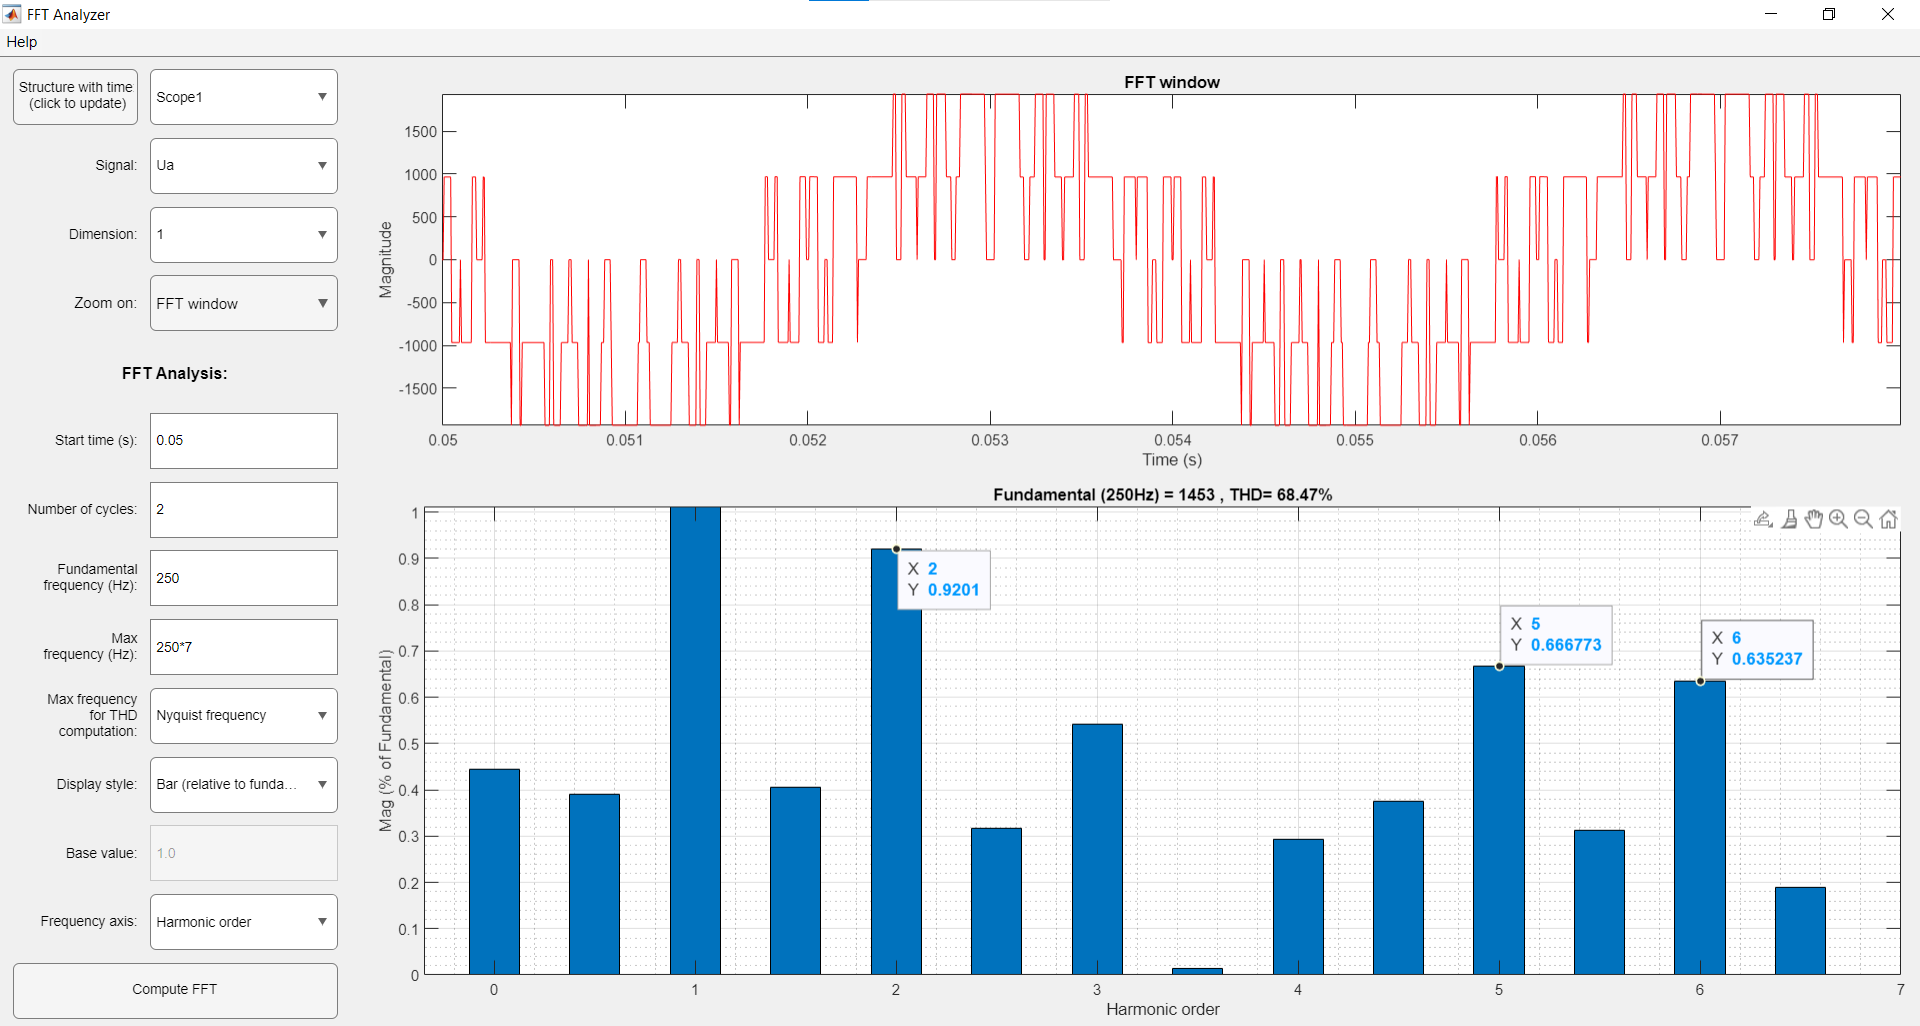

Рисунок 3. Спектральный анализ напряжения нагрузки (m1 = 0,8)

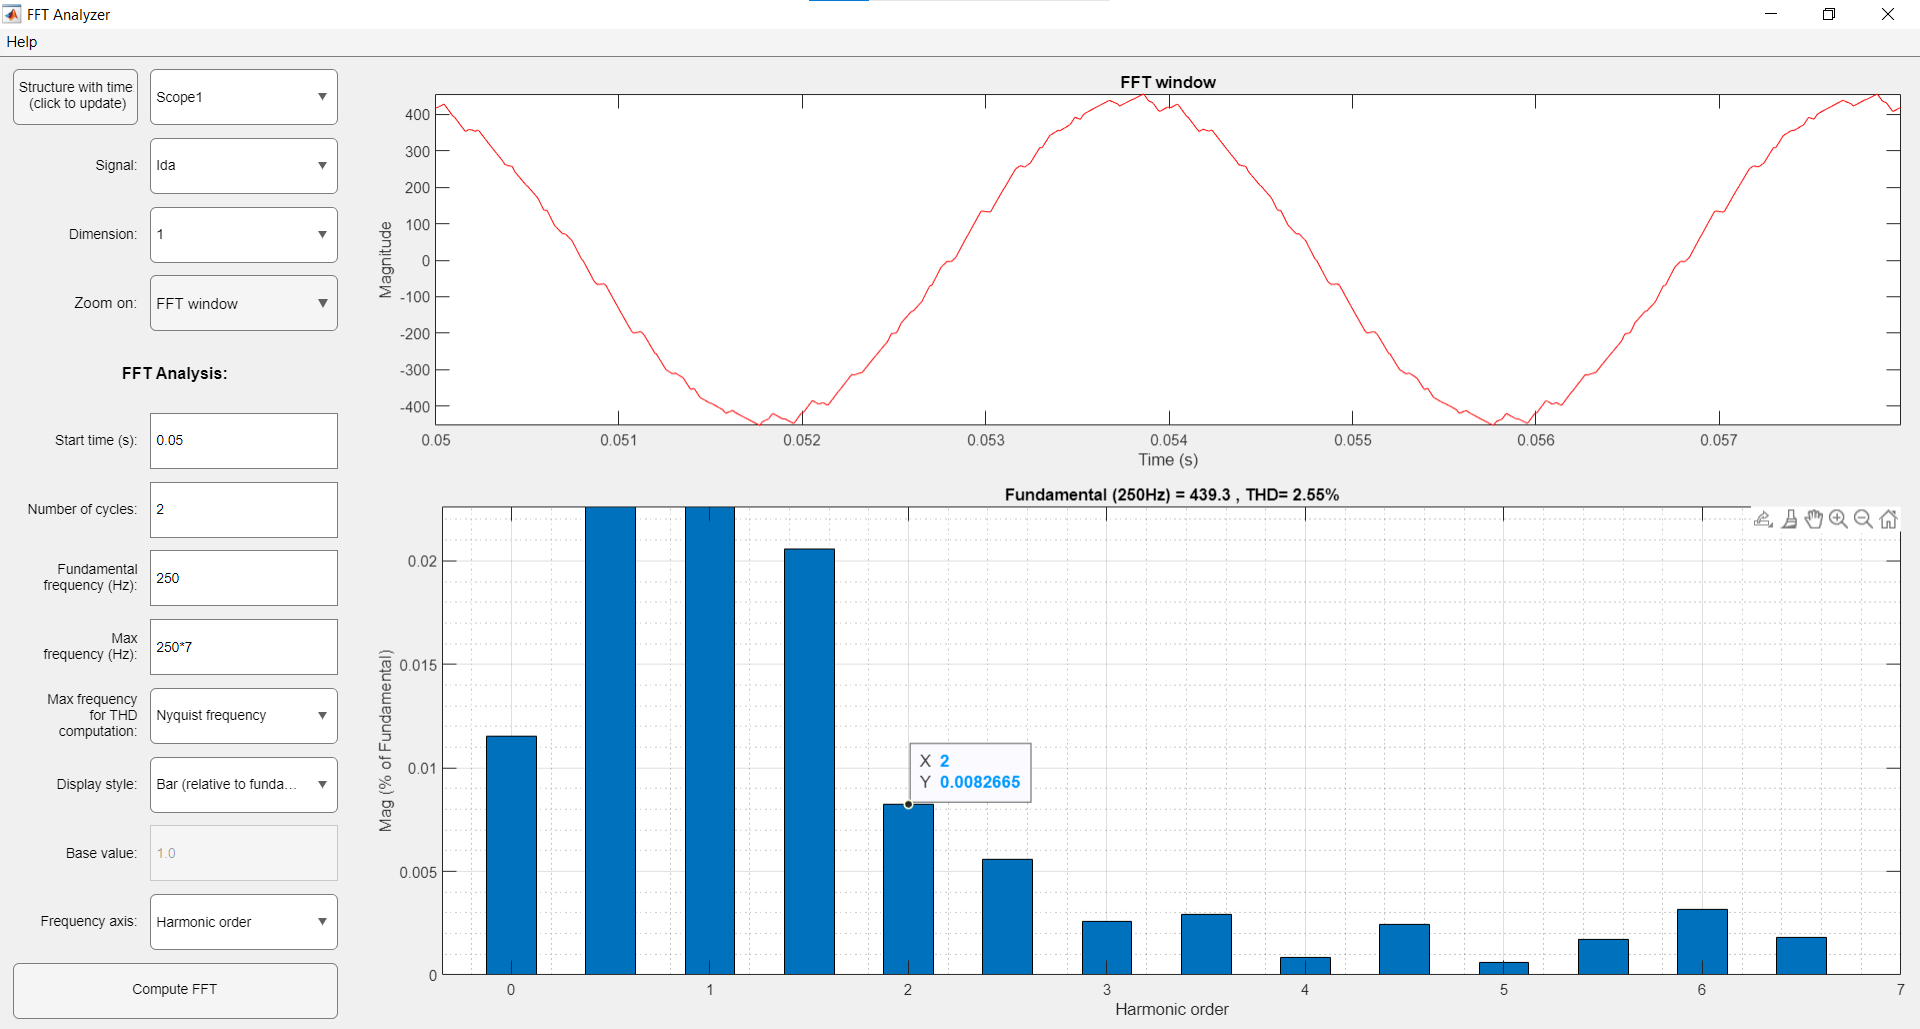

 Рисунок 4. Спектральный анализ тока нагрузки (m1 = 0,8) 

Спектральный анализ напряжения и тока нагрузки для величины коэффициента модуляции напряжения m2 = 1,2 изображен на рисунках 5 и 6:

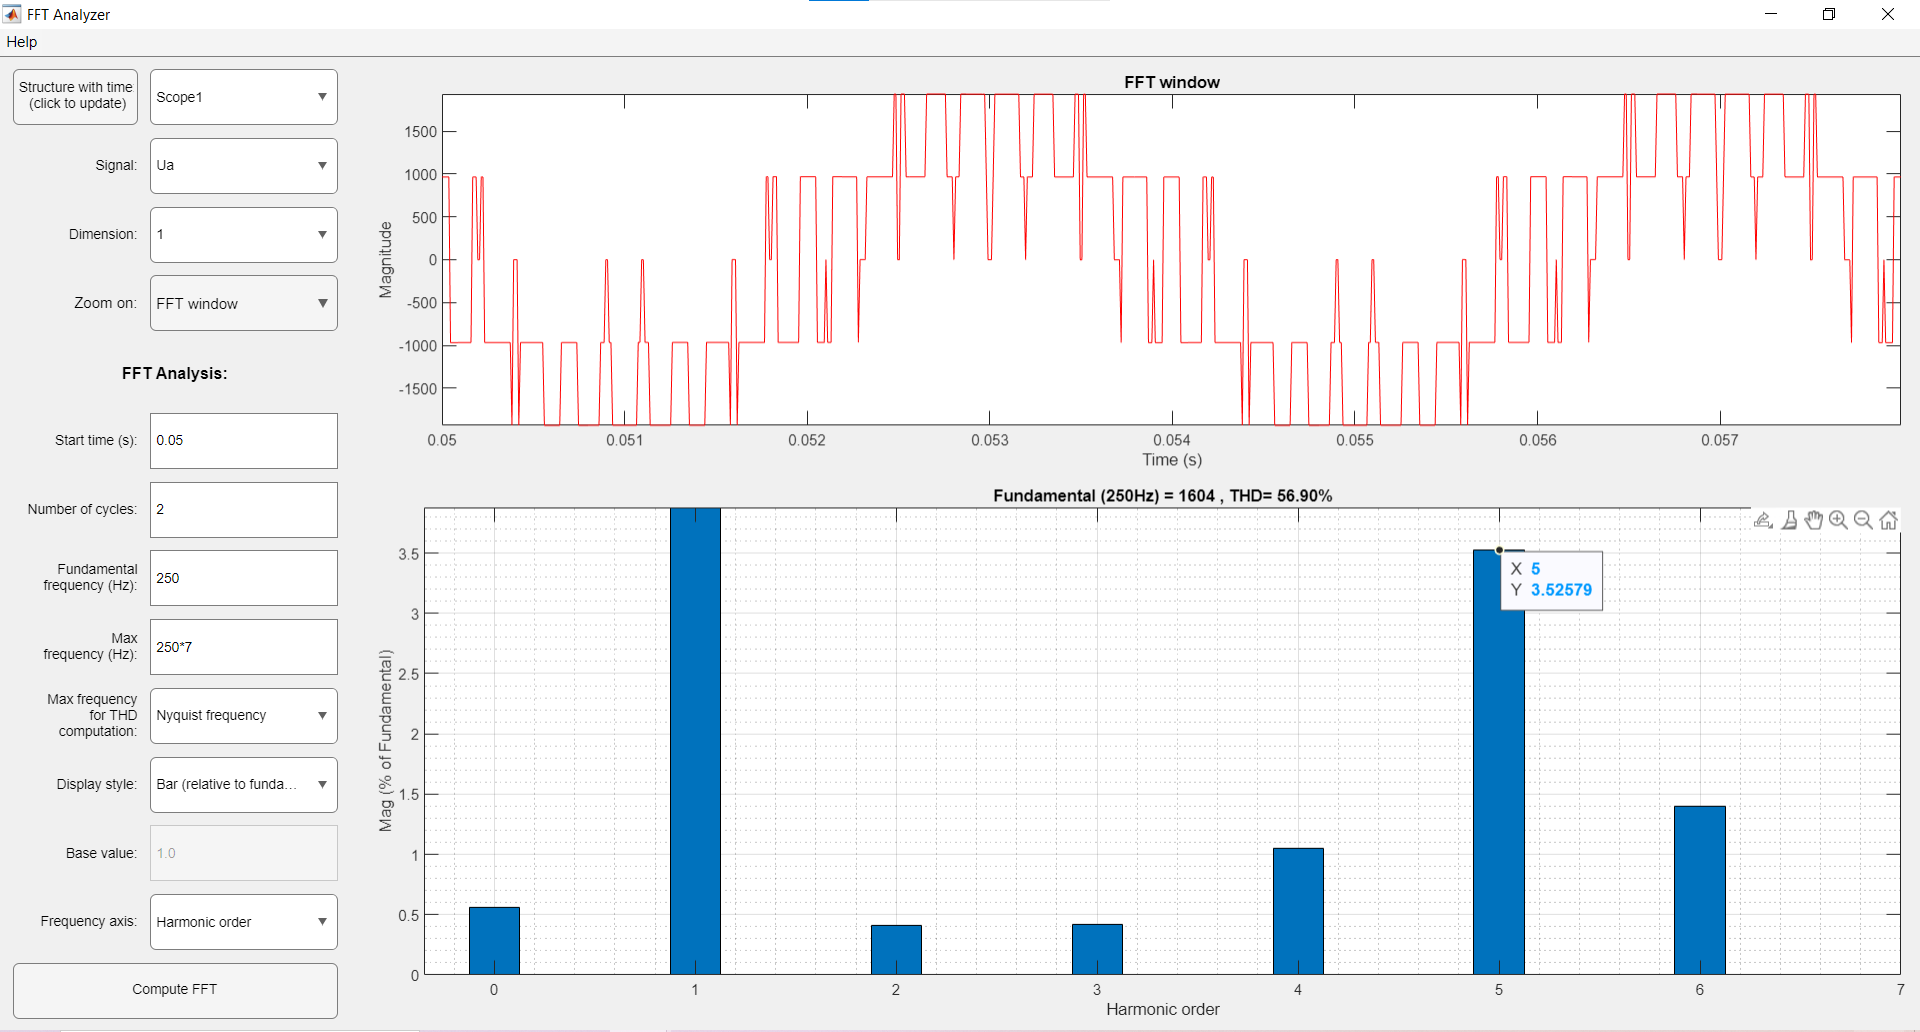

Рисунок 5. Спектральный анализ напряжения нагрузки (m2 = 1,2)

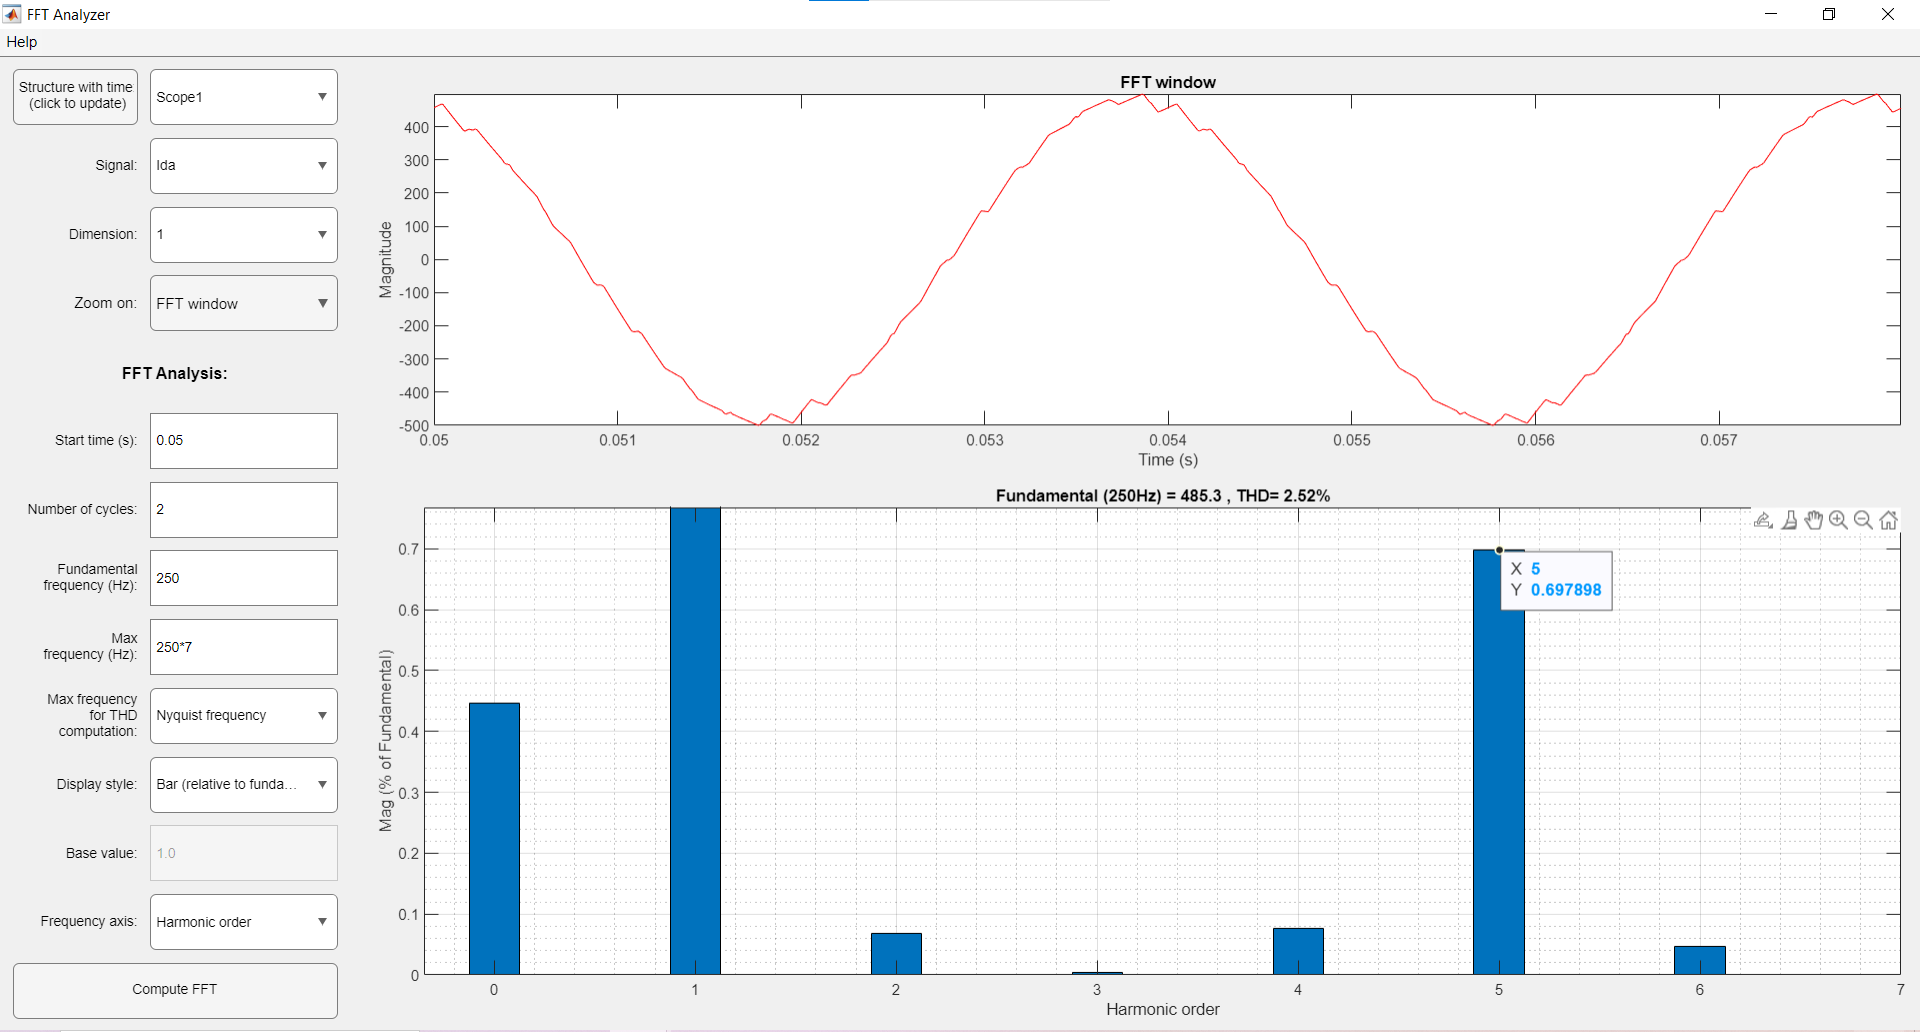

Рисунок 6. Спектральный анализ тока нагрузки (m2 = 1,2)

Для определения абсолютных значений гармонических составляющих в вольтах и амперах воспользуемся формулами:

Пример расчета для опыта при m1 = 0,8; номер грамоники v = 2:

yv2U_1 = 0.92; % %
U_n1_max1 = 1448; % В.
U_nV_max1 = yv2U_1*U_n1_max1/100

U_nV_max1 = 13.3216

yv2I_1 = 0.0083; % %
I_n1_max1 = 439.4; % А.
I_nV_max1 = yv2I_1*I_n1_max1/100

I_nV_max1 = 0.0365

Пример расчета для опыта при m2 = 1,2; номер грамоники v = 5:

yv5U_2 = 3.53; % %
U_n1_max2 = 1599; % В.
U_nV_max2 = yv5U_2*U_n1_max2/100

U_nV_max2 = 56.4447

yv5I_2 = 0.7; % %
I_n1_max2 = 485.5; % А.
I_nV_max2 = yv5I_2*I_n1_max2/100

I_nV_max2 = 3.3985

**11. Осциллограммы напряжений и токов на нагрузке, тока источника  питания, фазного напряжения, модулирующего напряжения и напряжения генератора пилообразного сигнала, импульсов управления транзисторами инвертора, напряжения и ток полупроводникового модуля инвертора.**

Масштаб построения осцилограмм по горизонали:

x.min = 0.09;
x.max = 0.1;

**10.1. Диаграммы токов и напряжений (Rн = 1 Ом, m = 1):**

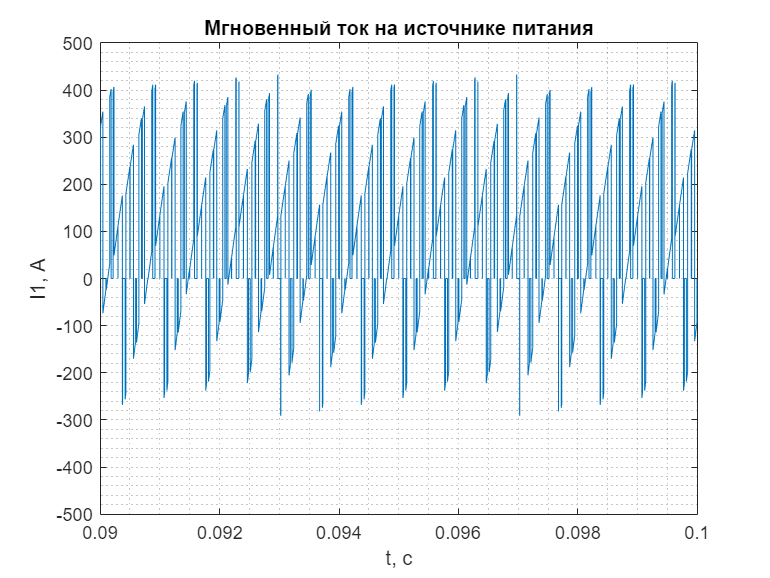

for R = 1
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    Modulation_Index.m = m0;
    sim('SHEST');
end
plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Мгновенный ток на источнике питания');
    xlim([x.min x.max]);
    ylim([-500 500]);

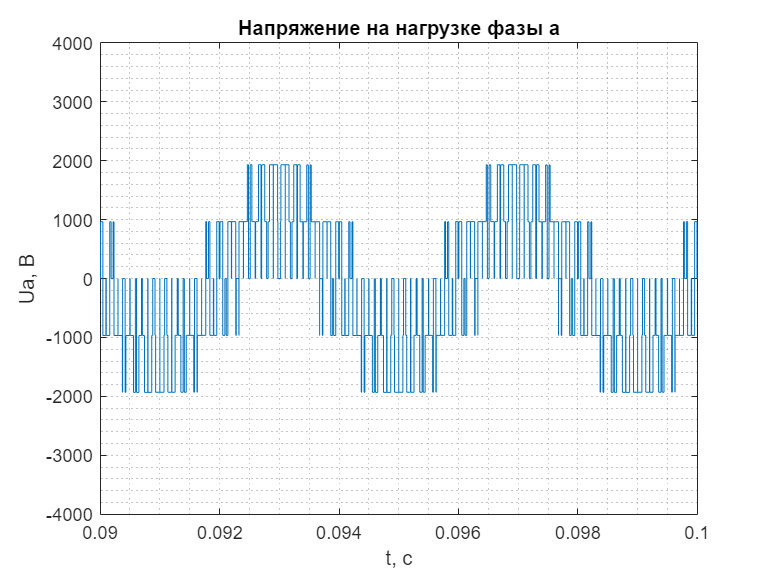

plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ua, В');
    title('Напряжение на нагрузке фазы а');
    xlim([x.min x.max]);
    ylim([-4000 4000]);

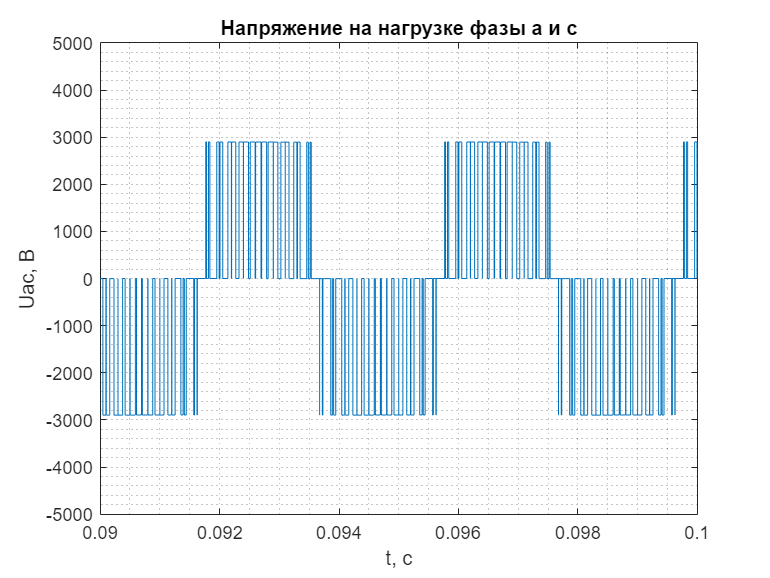

plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uac, В');
    title('Напряжение на нагрузке фазы а и c');
    xlim([x.min x.max]);
    ylim([-5000 5000]);

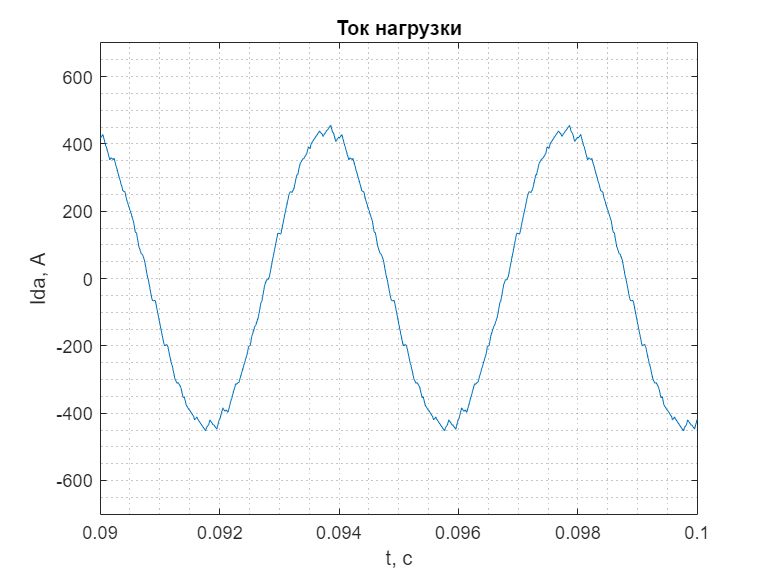

 plot(Scope1{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ida, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([-700 700]);

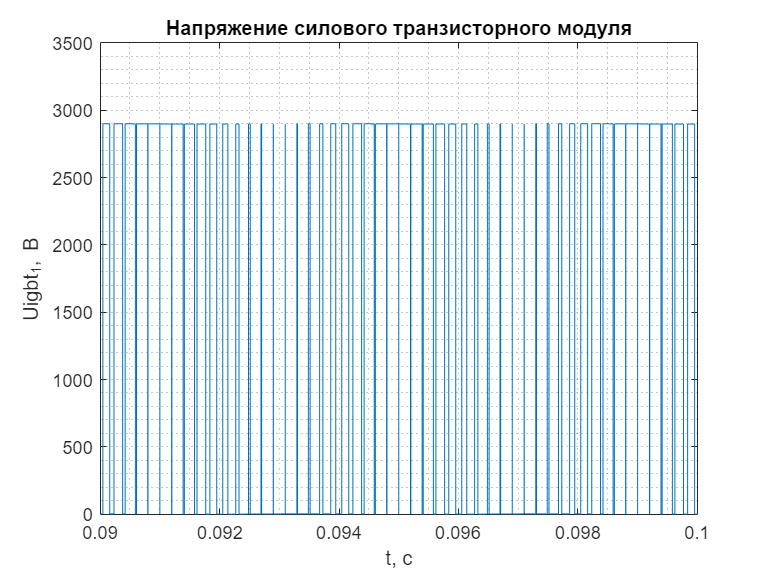

plot(Scope2{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uigbt_1, В');
    title('Напряжение силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([0 3500]);

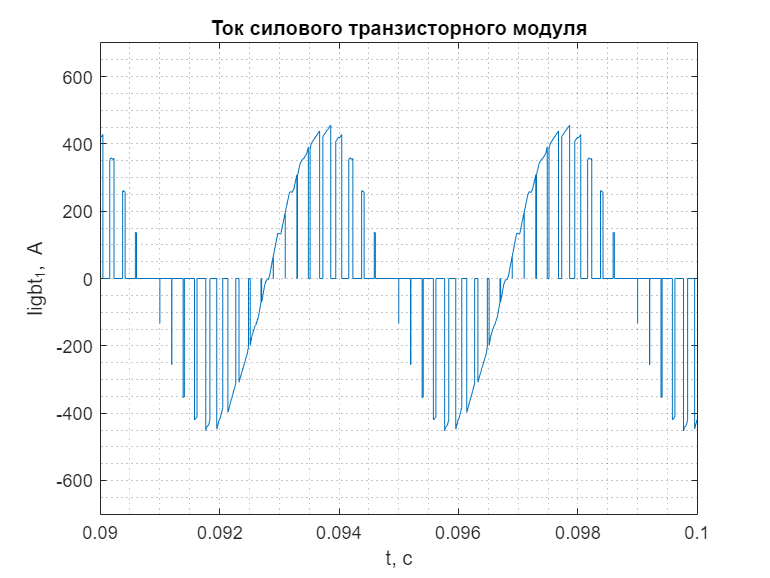

plot(Scope2{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iigbt_1, А');
    title('Ток силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([-700 700]); 

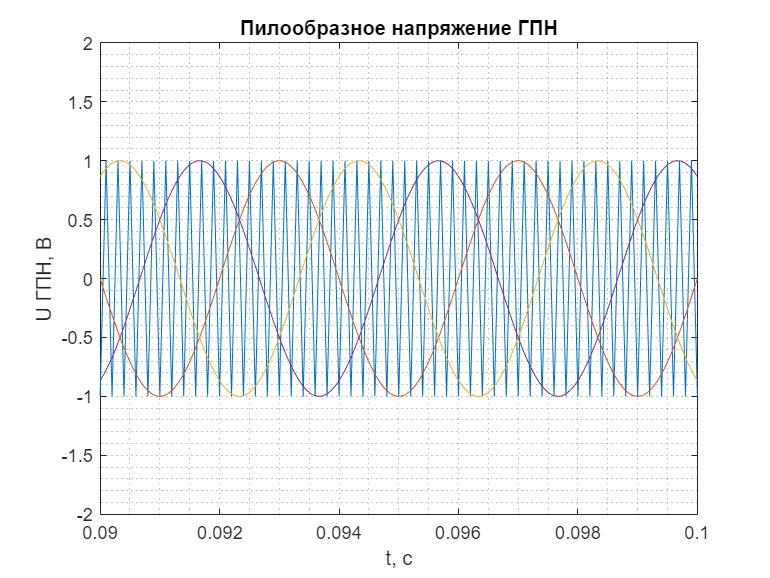

plot(Scope3{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);
    ylim([-2 2]);

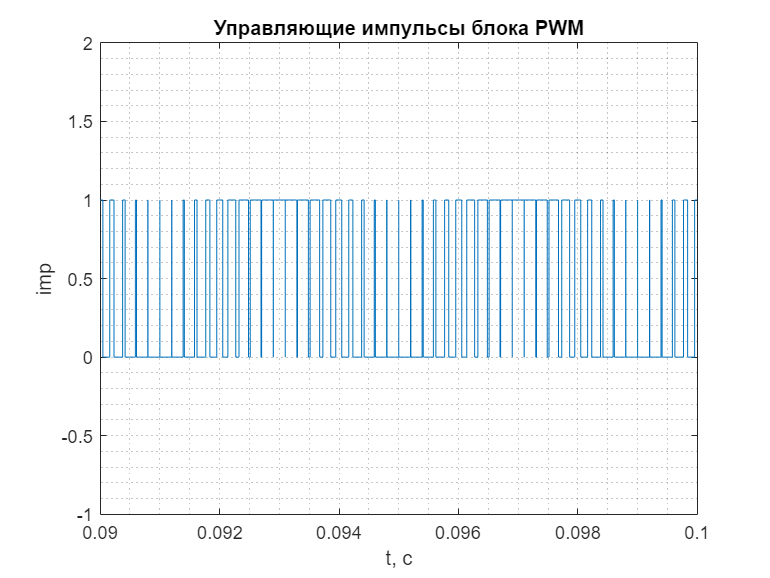

 plot(Scope3{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

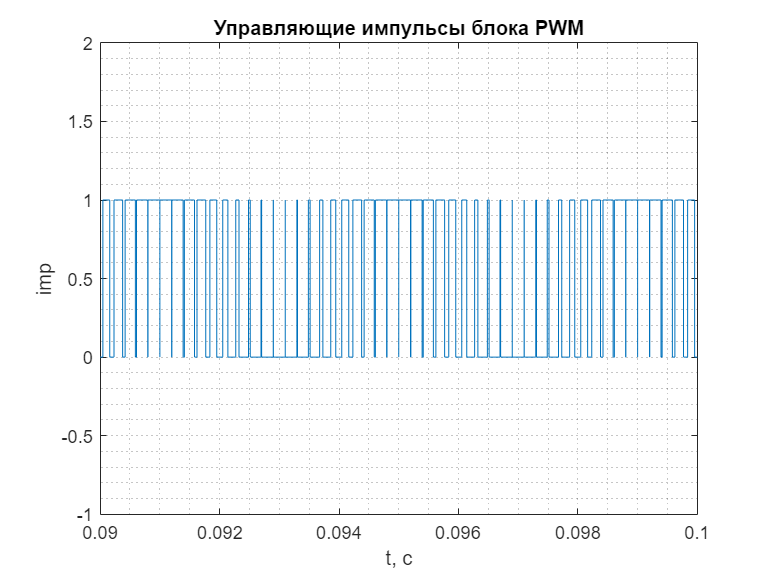

 plot(Scope3{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

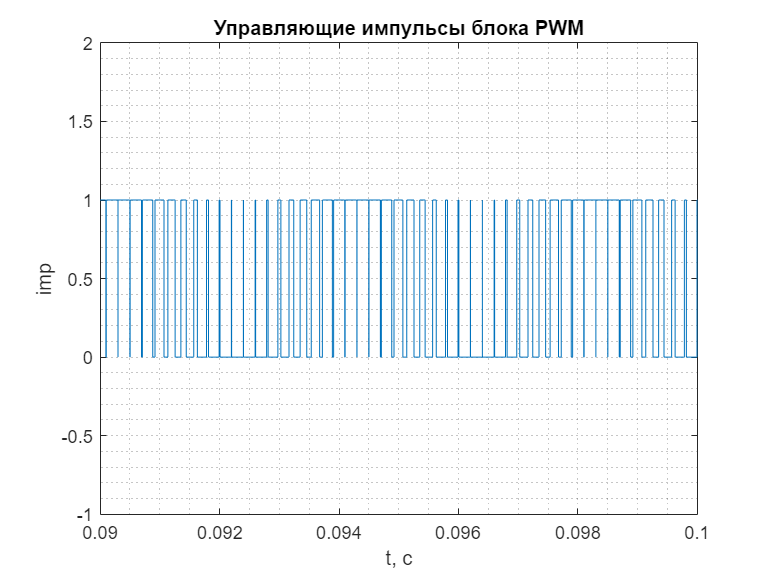

plot(Scope3{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

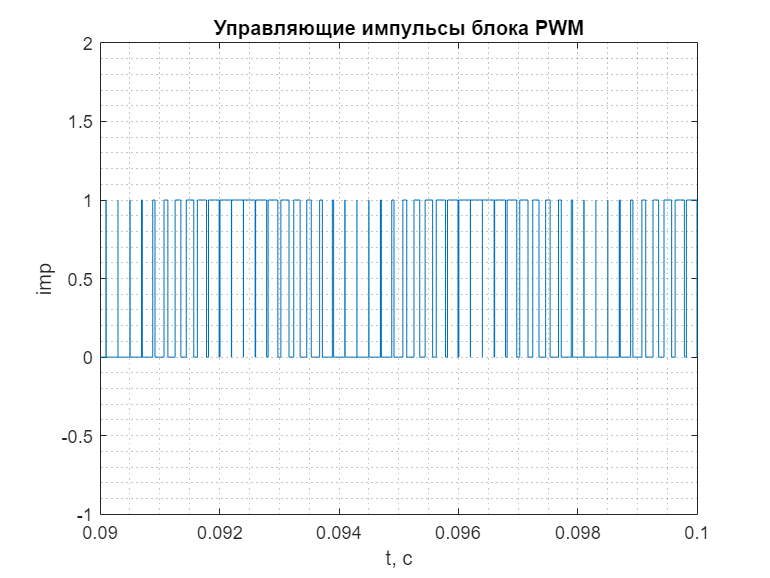

 plot(Scope3{5}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

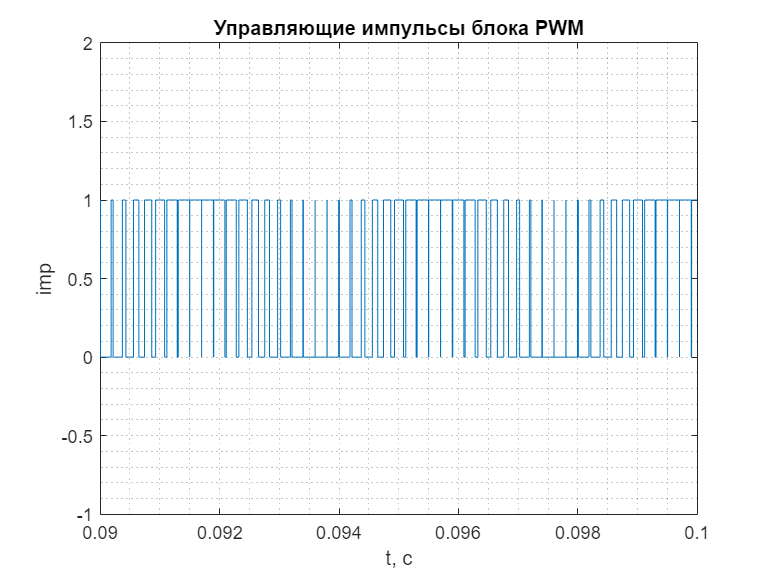

 plot(Scope3{6}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

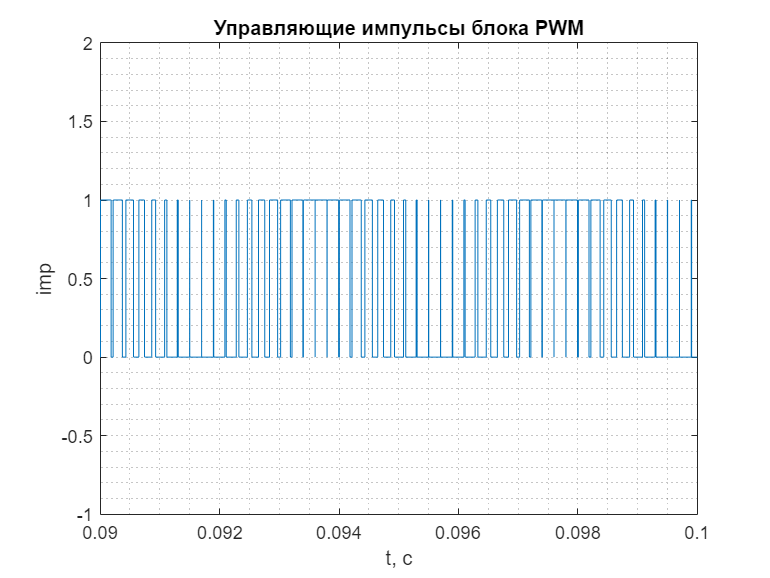

 plot(Scope3{7}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

**10.2. Диаграммы токов и напряжений (Rн = 5 Ом, m = 1):**

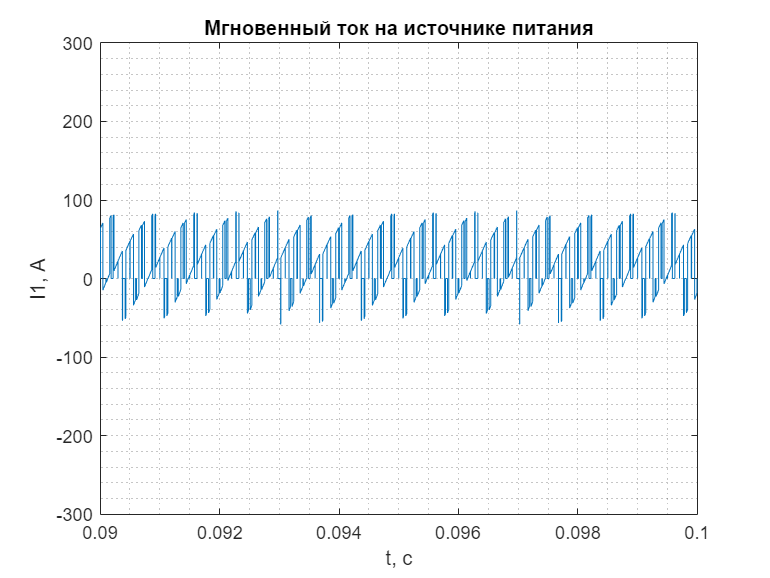

for R = 5
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    Modulation_Index.m = m0;
    sim('SHEST');
end
plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Мгновенный ток на источнике питания');
    xlim([x.min x.max]);
    ylim([-300 300]);

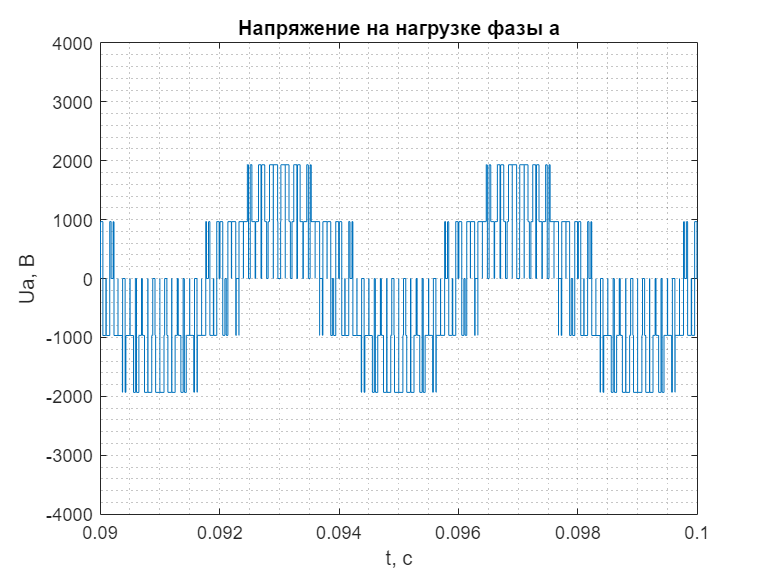

plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ua, В');
    title('Напряжение на нагрузке фазы а');
    xlim([x.min x.max]);
    ylim([-4000 4000]);

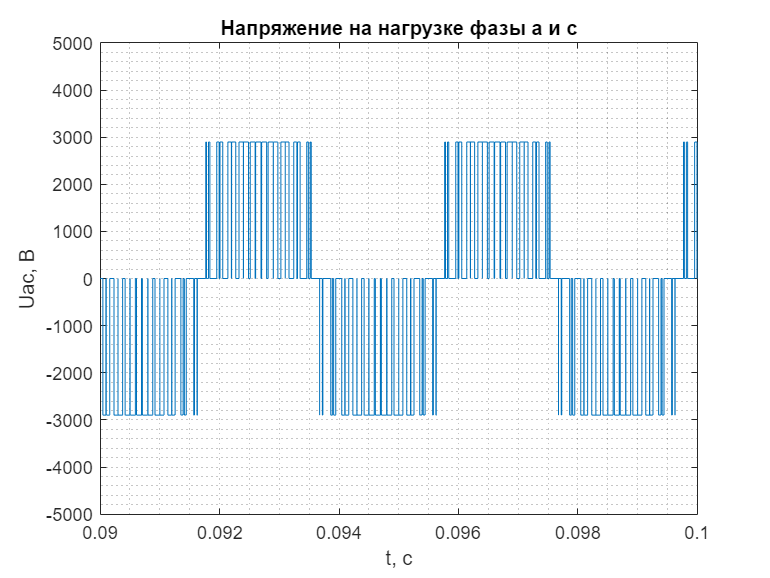

plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uac, В');
    title('Напряжение на нагрузке фазы а и c');
    xlim([x.min x.max]);
    ylim([-5000 5000]);

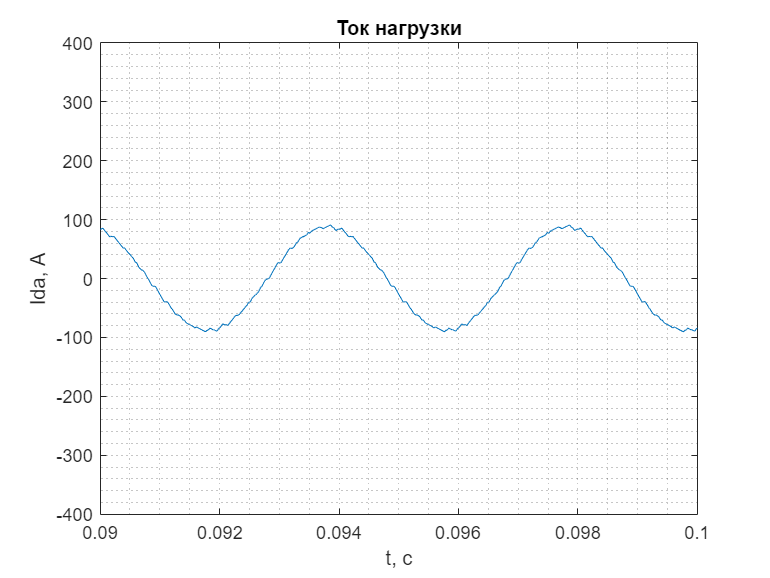

 plot(Scope1{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ida, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([-400 400]);

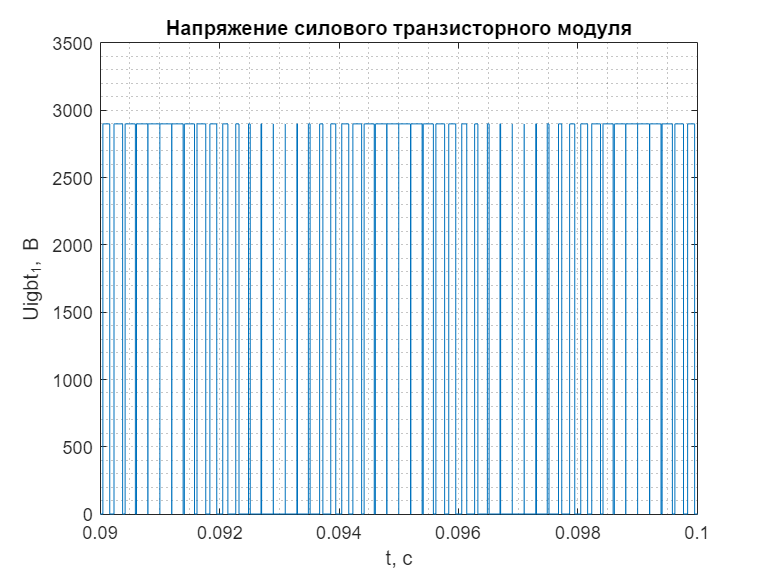

plot(Scope2{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uigbt_1, В');
    title('Напряжение силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([0 3500]);

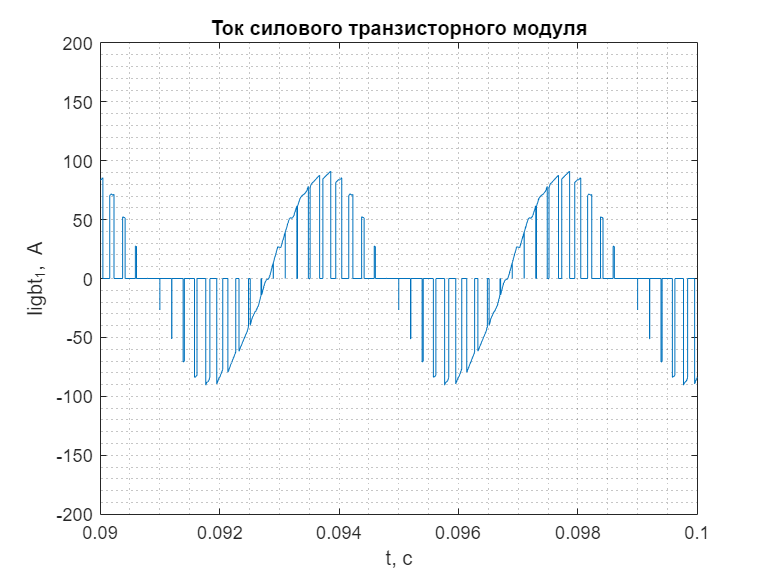

plot(Scope2{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iigbt_1, А');
    title('Ток силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([-200 200]); 

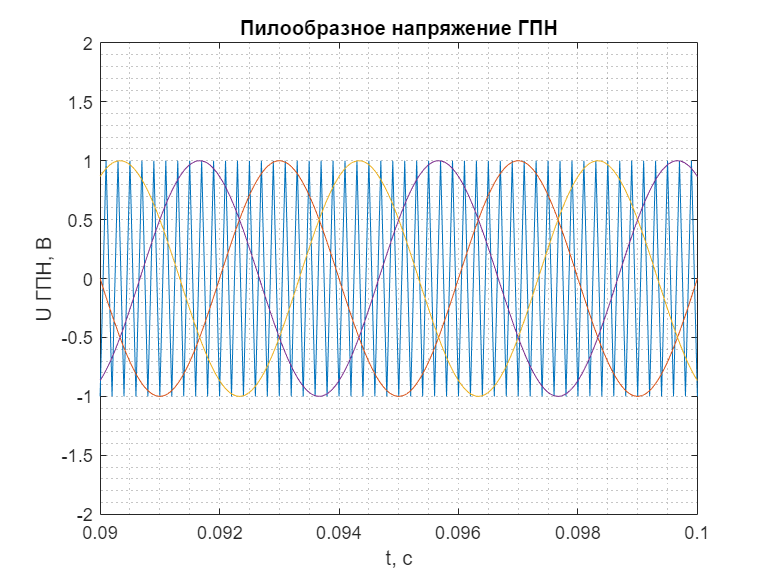

plot(Scope3{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);
    ylim([-2 2]);

 plot(Scope3{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

plot(Scope3{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{5}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{6}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{7}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

**10.3. Диаграммы токов и напряжений (Rн = 10 Ом, m = 1):**

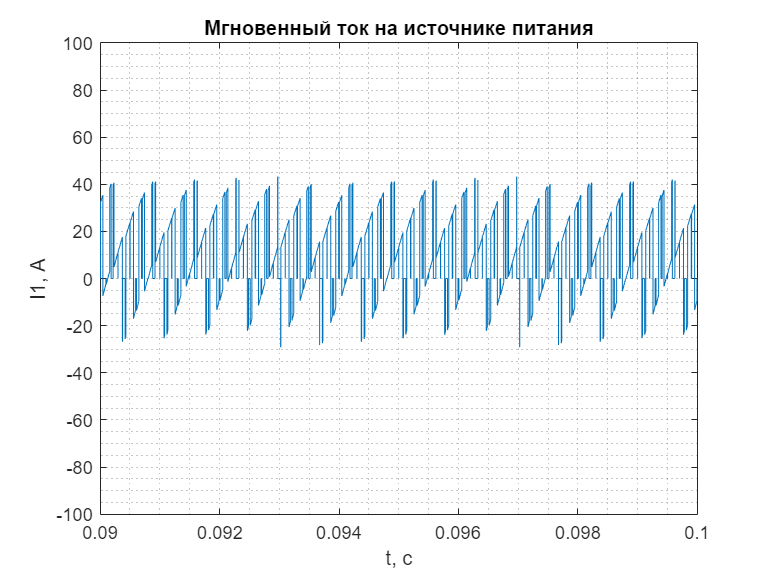

for R = 10
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    Modulation_Index.m = m0;
    sim('SHEST');
end
plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Мгновенный ток на источнике питания');
    xlim([x.min x.max]);
    ylim([-100 100]);

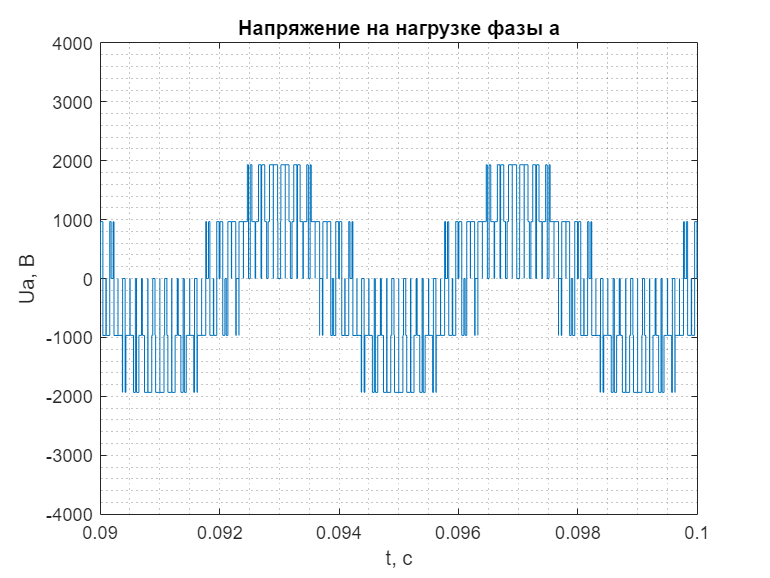

plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ua, В');
    title('Напряжение на нагрузке фазы а');
    xlim([x.min x.max]);
    ylim([-4000 4000]);

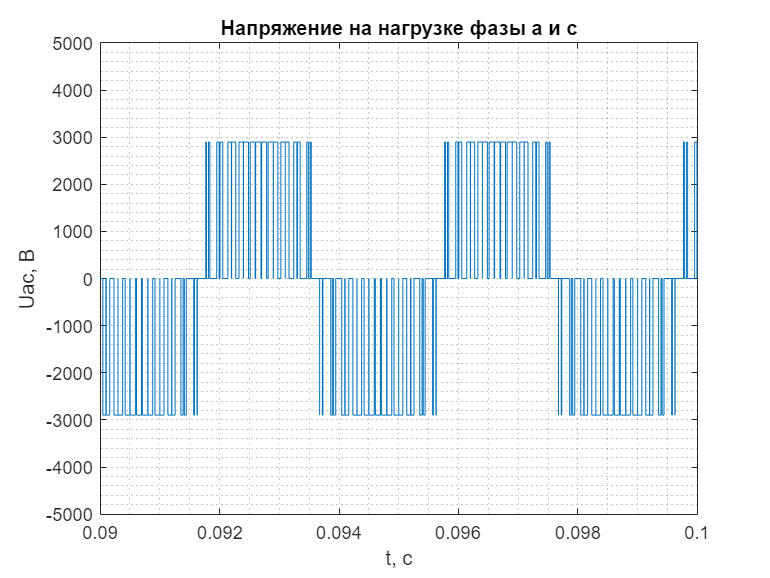

plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uac, В');
    title('Напряжение на нагрузке фазы а и c');
    xlim([x.min x.max]);
    ylim([-5000 5000]);

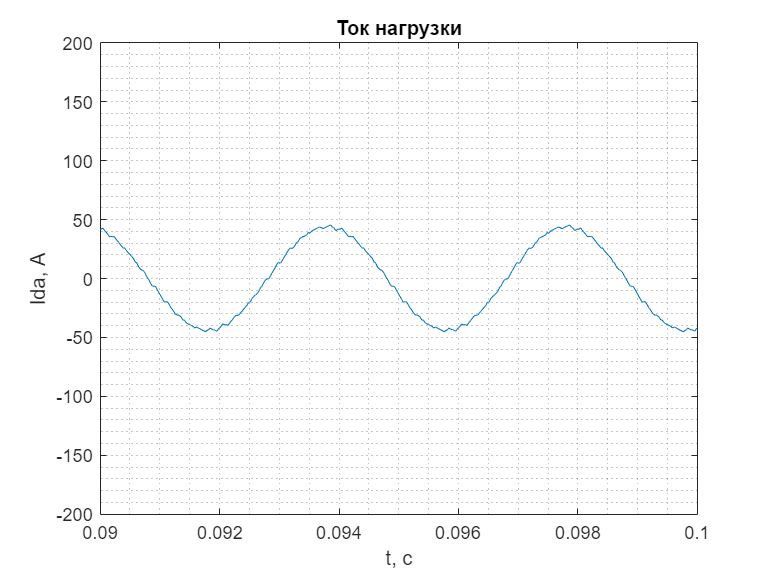

 plot(Scope1{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ida, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([-200 200]);

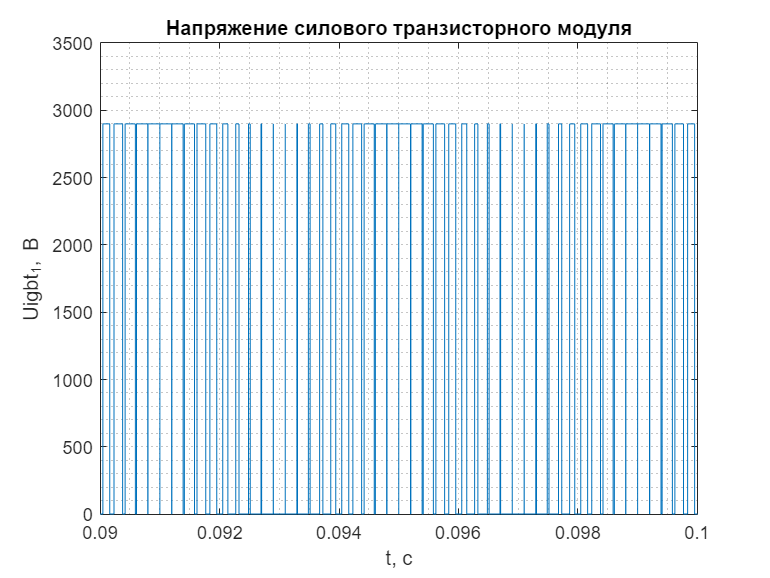

plot(Scope2{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uigbt_1, В');
    title('Напряжение силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([0 3500]);

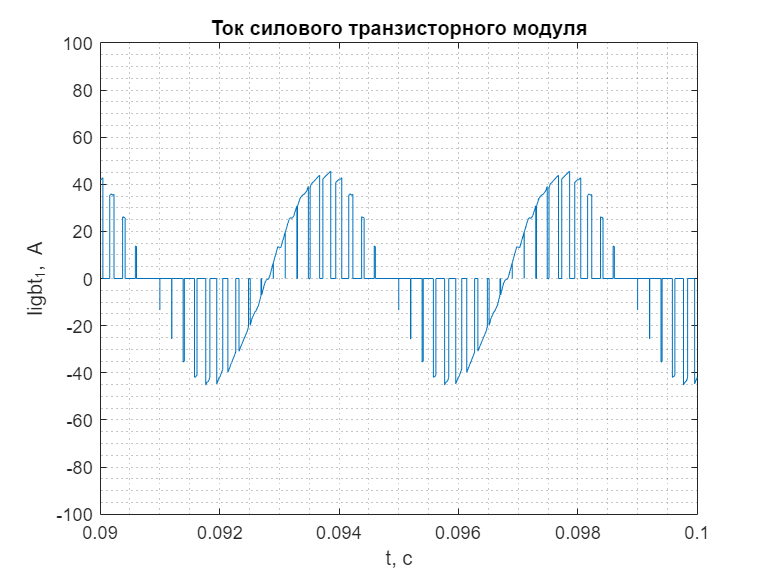

plot(Scope2{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iigbt_1, А');
    title('Ток силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([-100 100]); 

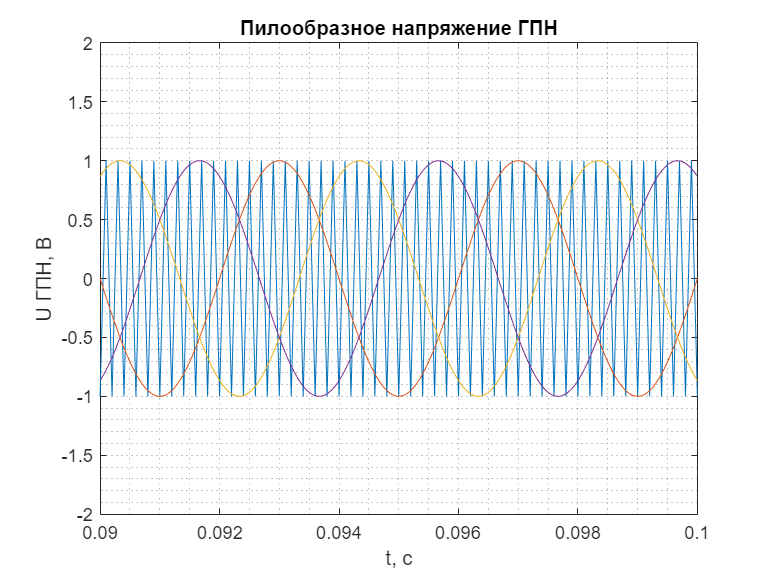

plot(Scope3{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);
    ylim([-2 2]);

 plot(Scope3{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

plot(Scope3{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{5}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{6}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

 plot(Scope3{7}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

**10.4. Диаграммы токов и напряжений (Rн = 10 Ом., m = 0.8):**

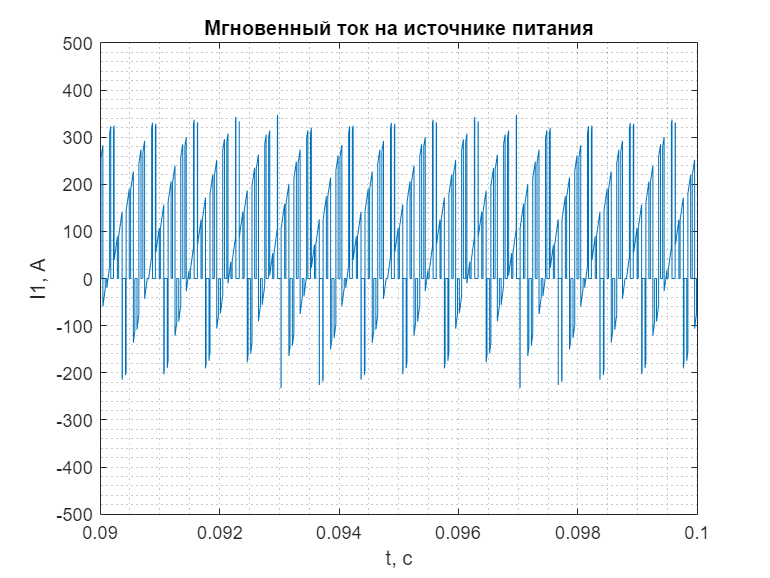

for R = 1
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    Modulation_Index.m = data.m1;
    sim('SHEST');
end
plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Мгновенный ток на источнике питания');
    xlim([x.min x.max]);
    ylim([-500 500]);

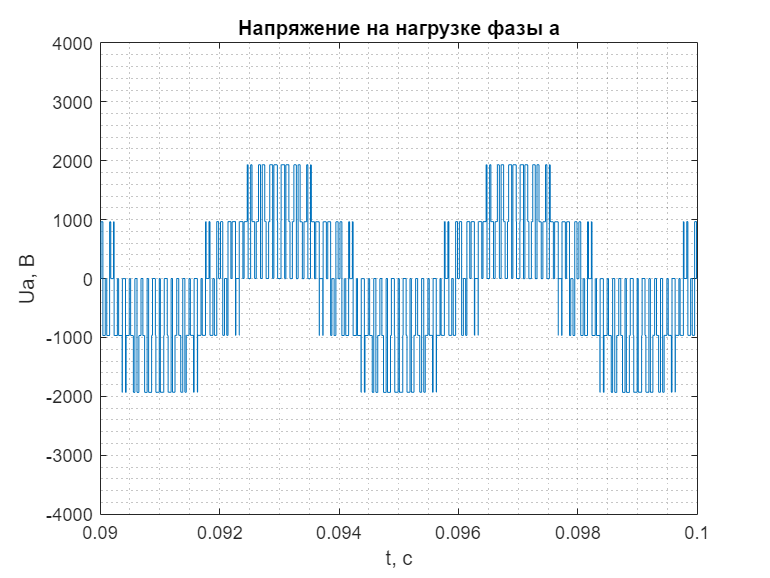

plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ua, В');
    title('Напряжение на нагрузке фазы а');
    xlim([x.min x.max]);
    ylim([-4000 4000]);

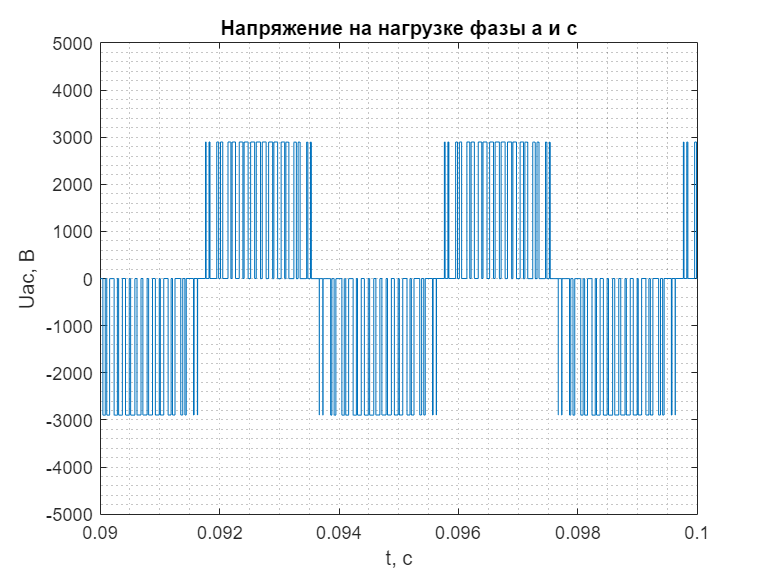

plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uac, В');
    title('Напряжение на нагрузке фазы а и c');
    xlim([x.min x.max]);
    ylim([-5000 5000]);

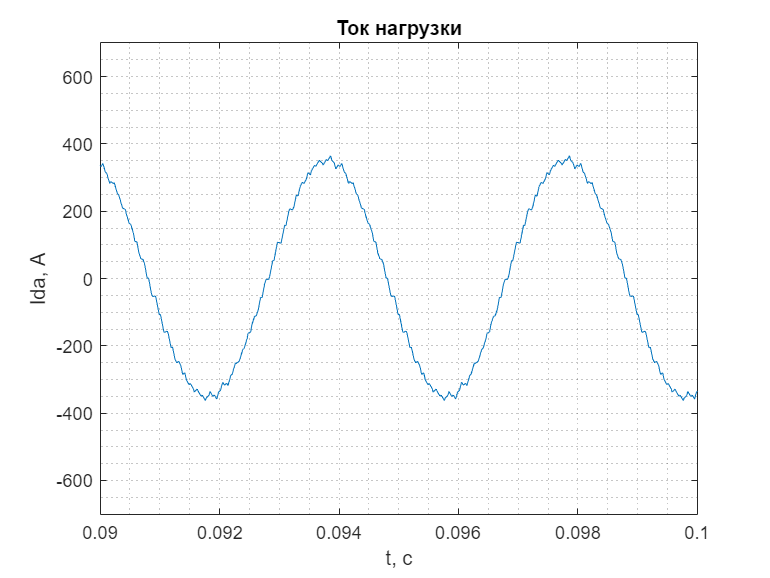

 plot(Scope1{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ida, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([-700 700]);

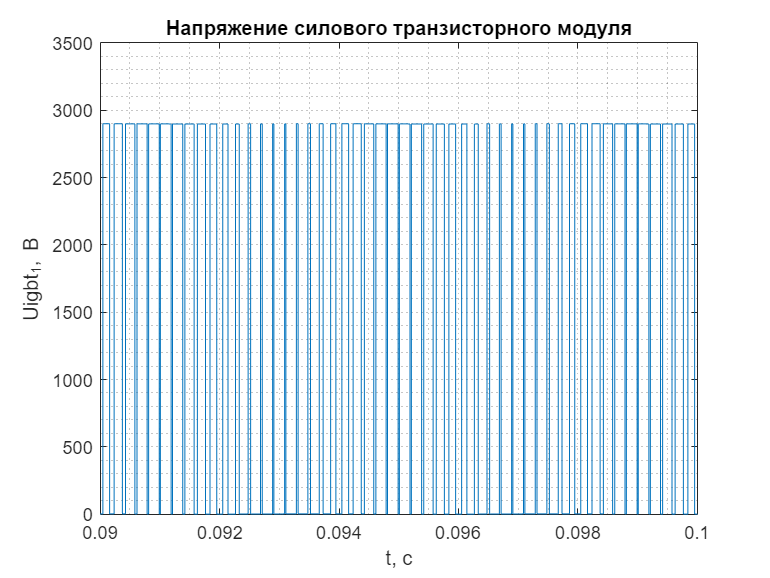

plot(Scope2{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uigbt_1, В');
    title('Напряжение силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([0 3500]);

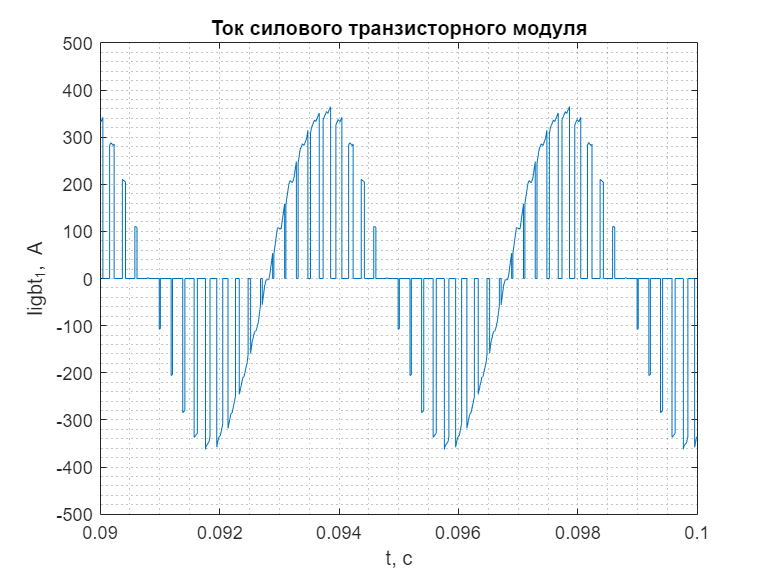

plot(Scope2{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iigbt_1, А');
    title('Ток силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([-500 500]); 

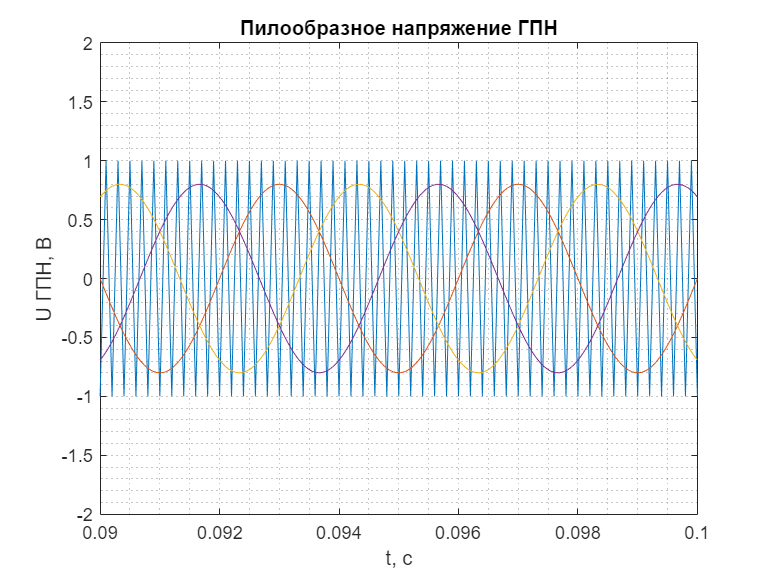

plot(Scope3{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);
    ylim([-2 2]);

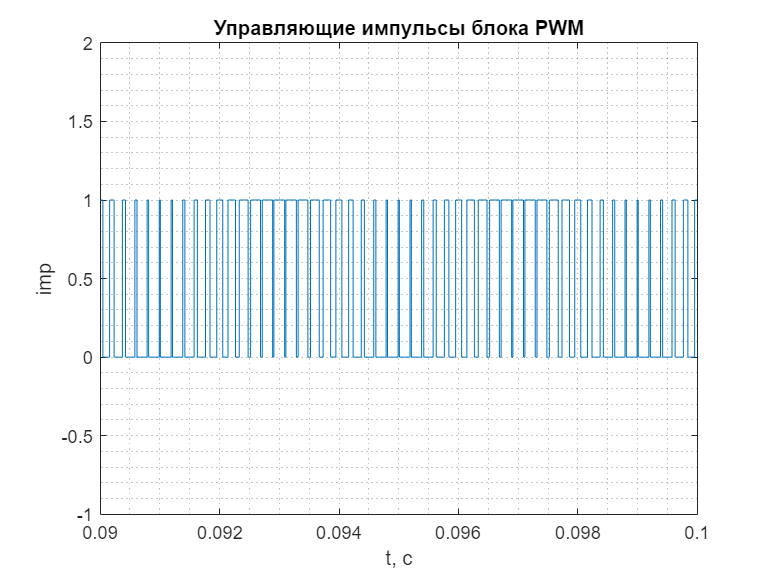

 plot(Scope3{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

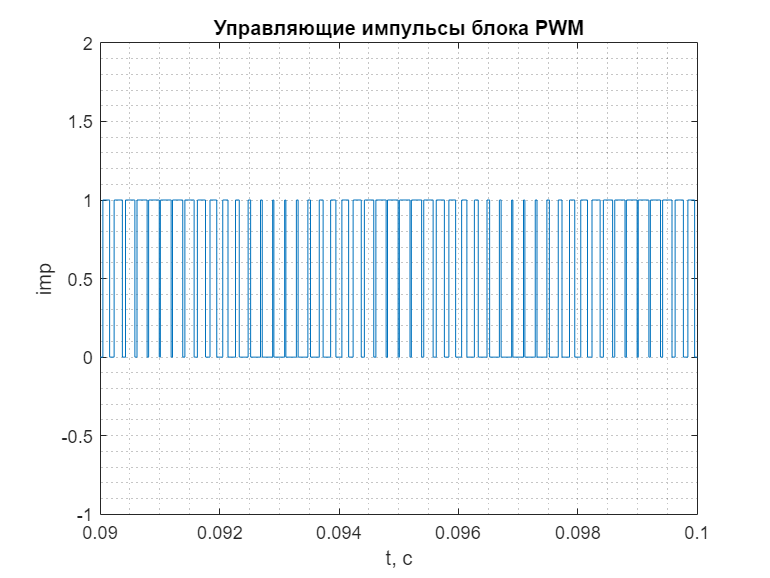

 plot(Scope3{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

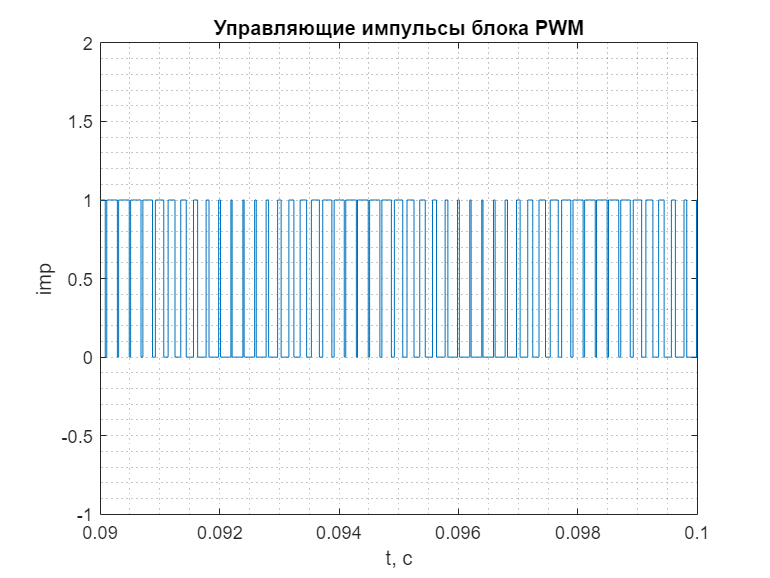

plot(Scope3{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

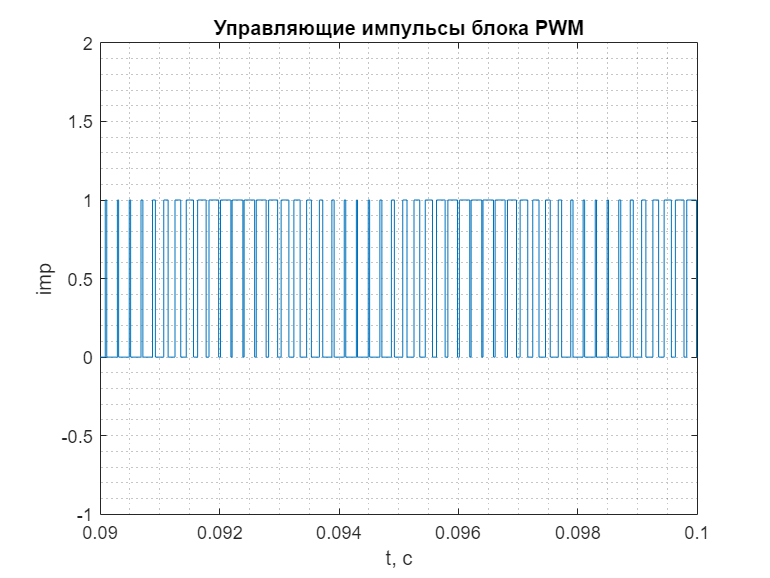

 plot(Scope3{5}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

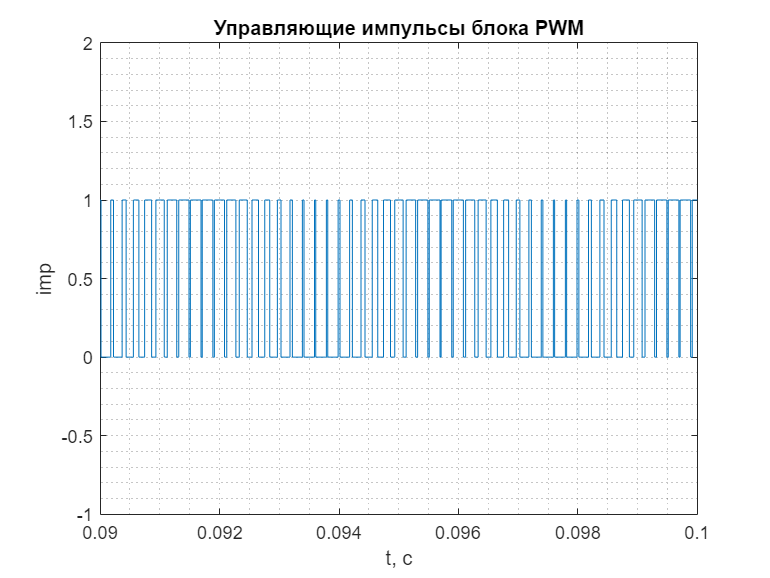

 plot(Scope3{6}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

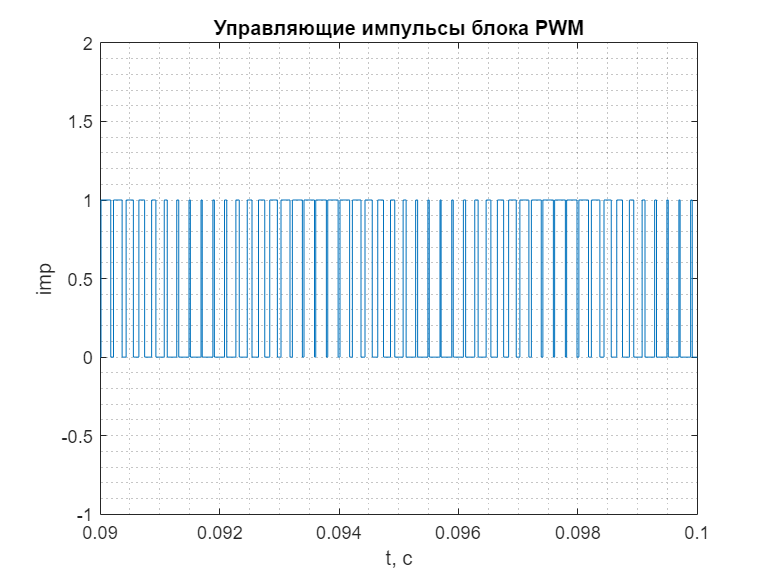

 plot(Scope3{7}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

**10.5. Диаграммы токов и напряжений (Rн = 10 Ом., m = 1.2):**

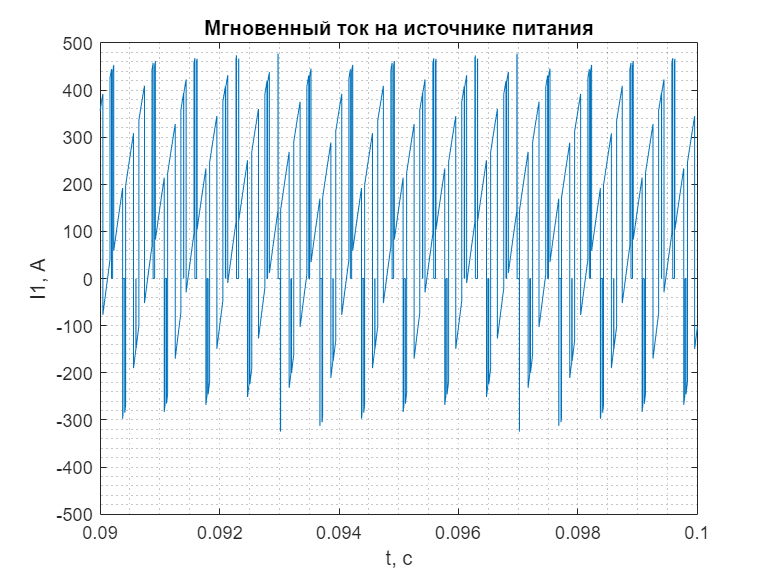

for R = 1
    Three_Phase_RL.Res = R;
    Three_Phase_RL.Ind = (Three_Phase_RL.Res/data.f0)*0.5;
    Modulation_Index.m = data.m2;
    sim('SHEST');
end
plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Мгновенный ток на источнике питания');
    xlim([x.min x.max]);
    ylim([-500 500]);

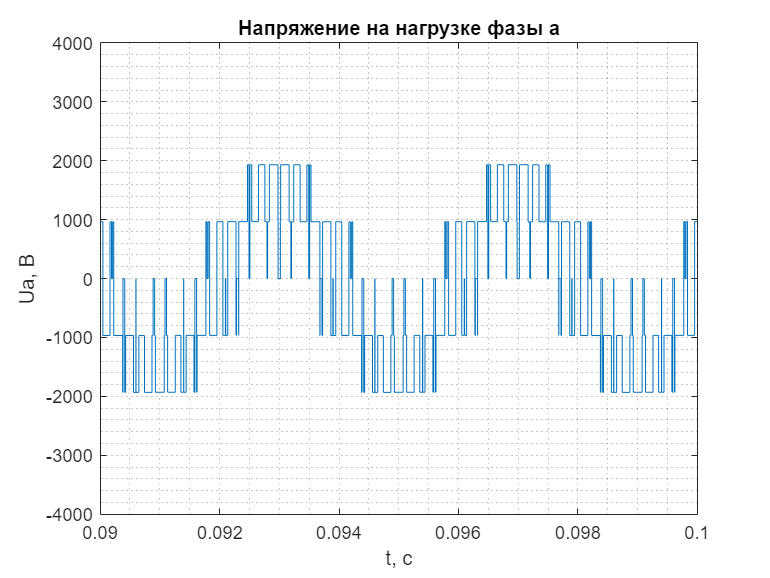

plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ua, В');
    title('Напряжение на нагрузке фазы а');
    xlim([x.min x.max]);
    ylim([-4000 4000]);

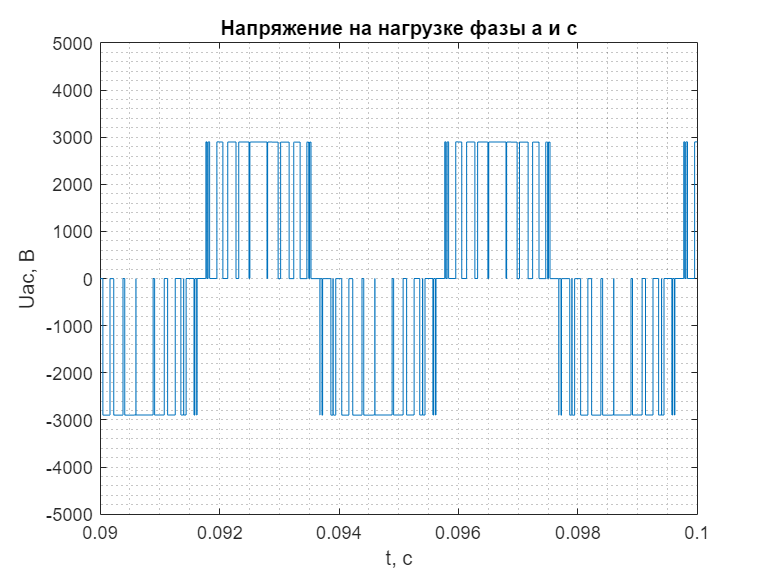

plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uac, В');
    title('Напряжение на нагрузке фазы а и c');
    xlim([x.min x.max]);
    ylim([-5000 5000]);

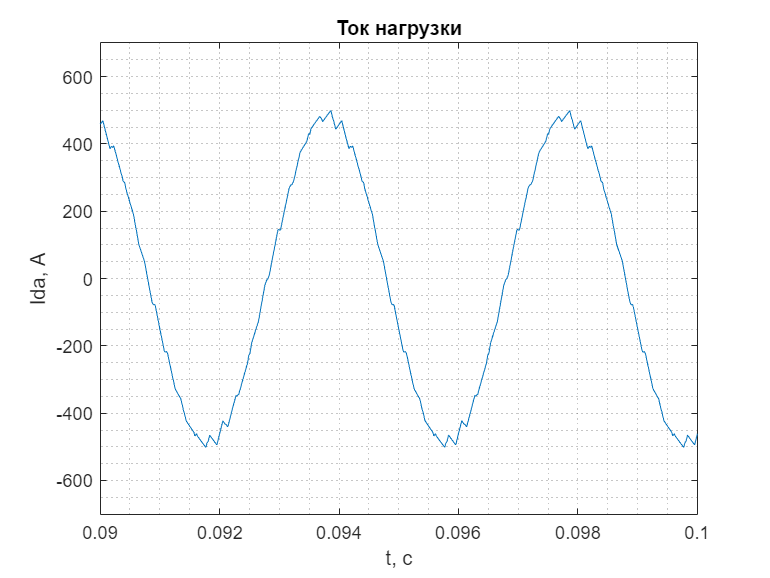

 plot(Scope1{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Ida, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([-700 700]);

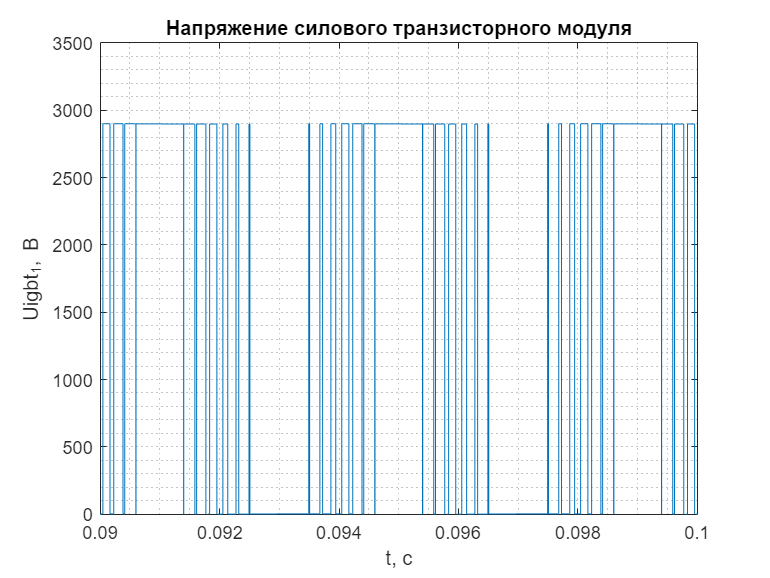

plot(Scope2{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uigbt_1, В');
    title('Напряжение силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([0 3500]);

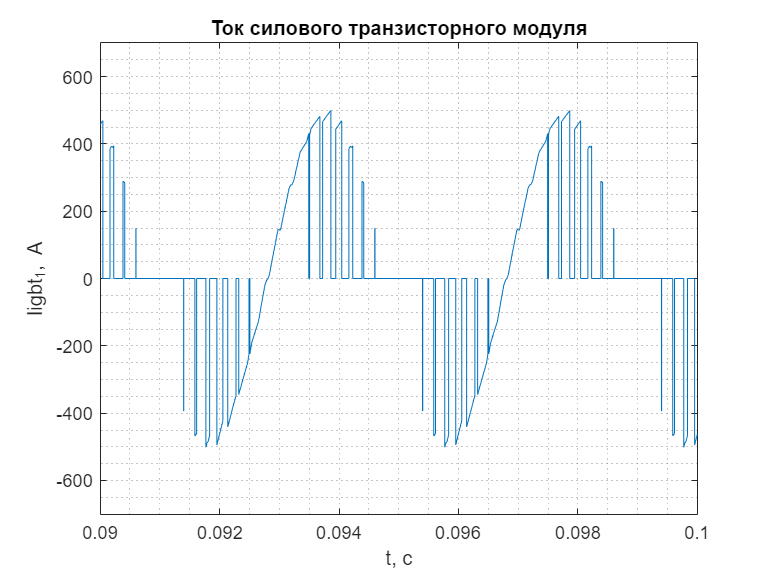

plot(Scope2{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iigbt_1, А');
    title('Ток силового транзисторного модуля');
    xlim([x.min x.max]);
    ylim([-700 700]); 

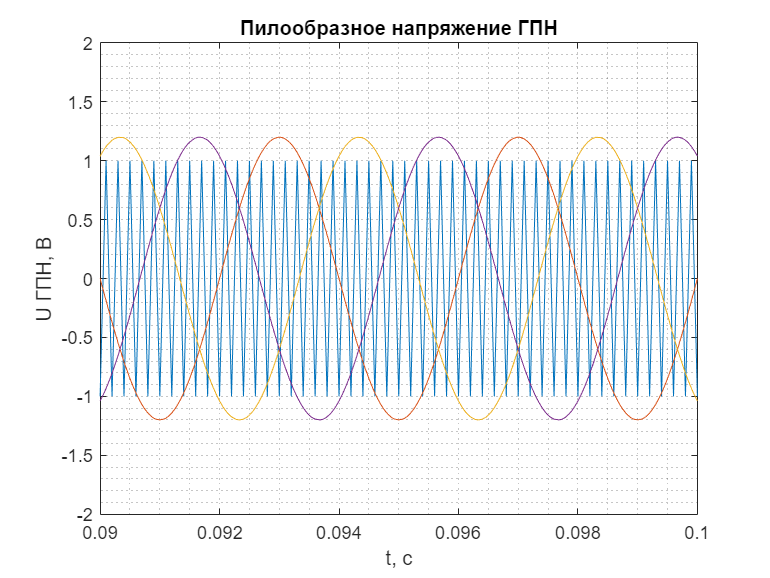

plot(Scope3{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);
    ylim([-2 2]);

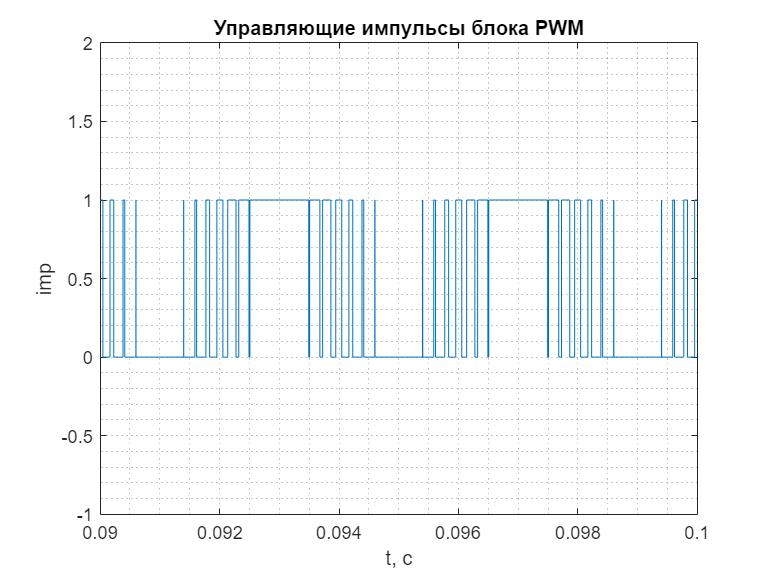

 plot(Scope3{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

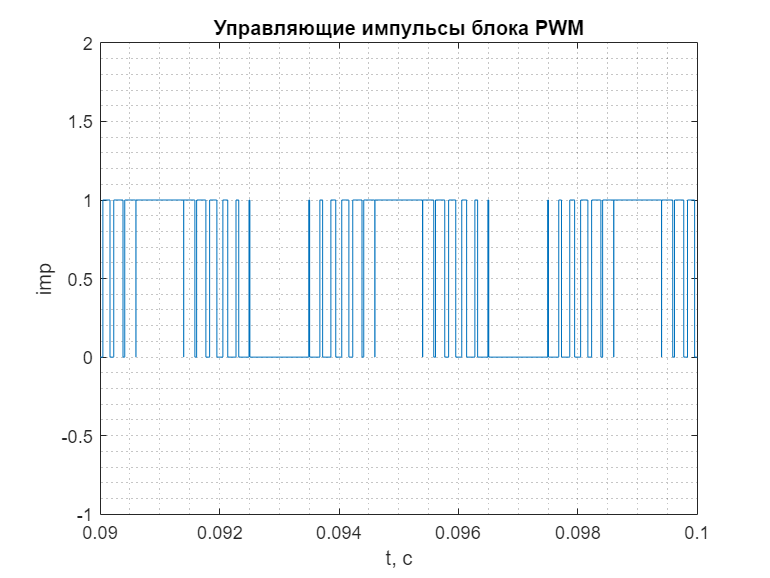

 plot(Scope3{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

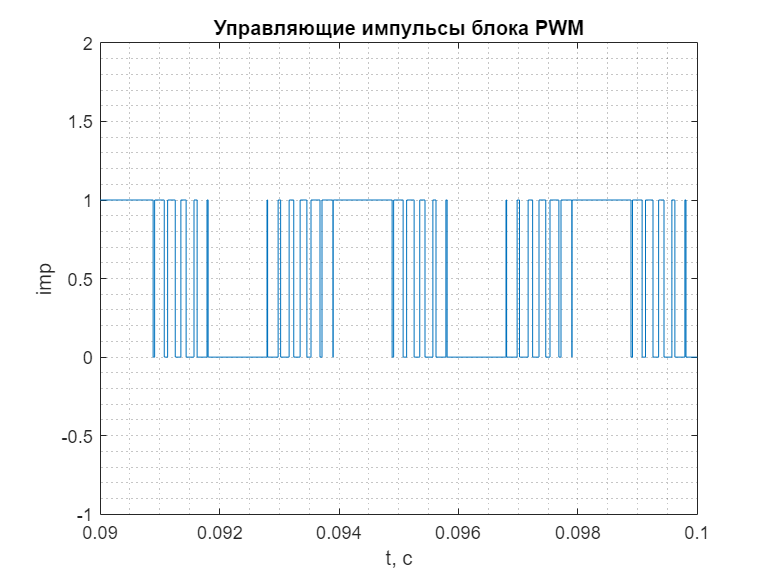

plot(Scope3{4}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

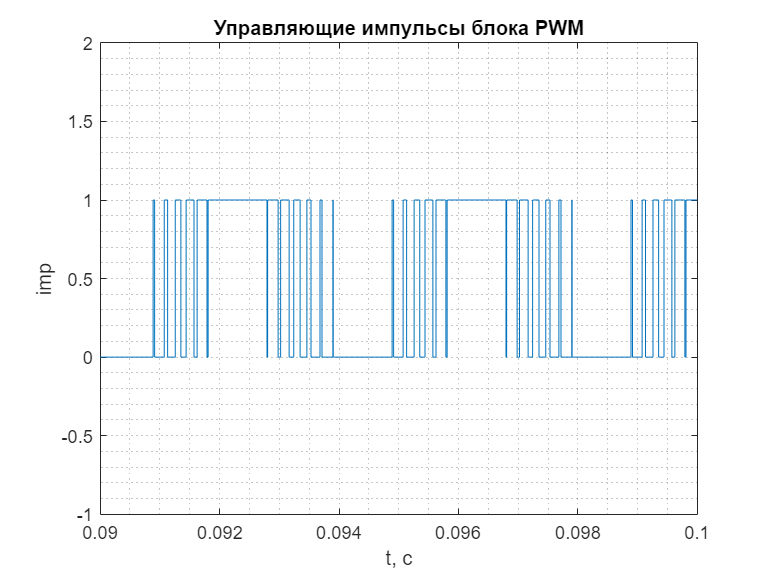

 plot(Scope3{5}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

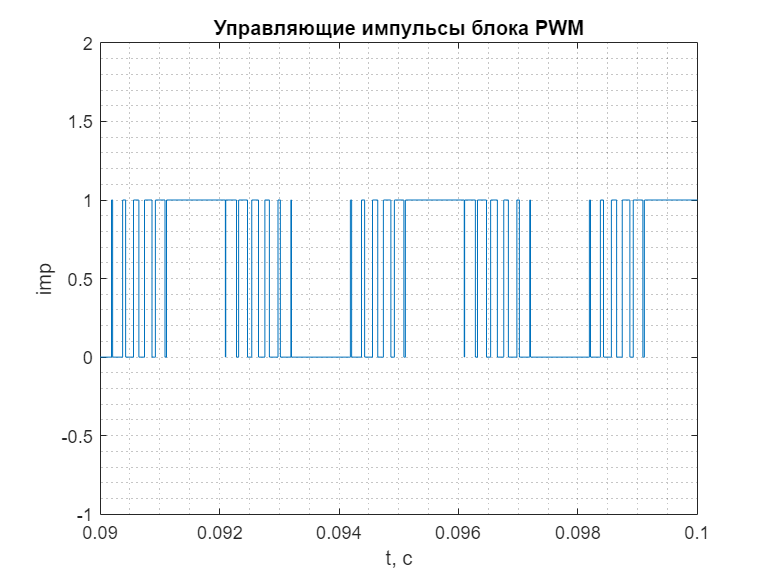

 plot(Scope3{6}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

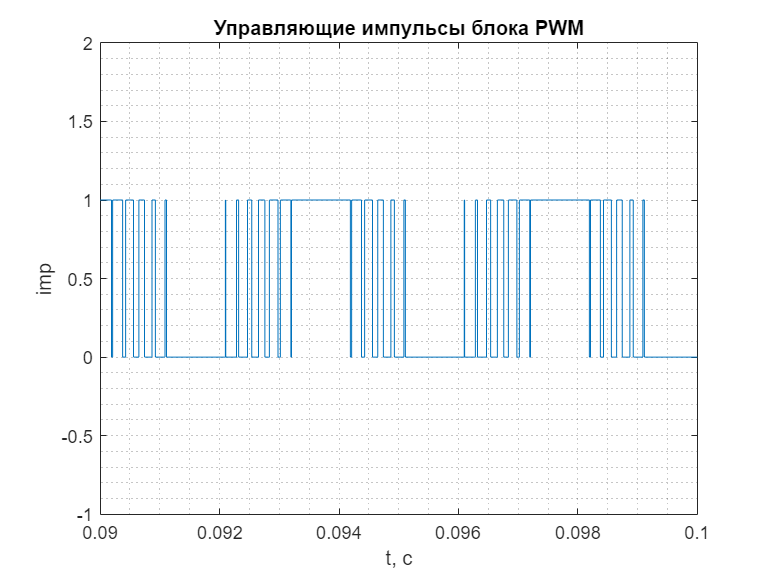

 plot(Scope3{7}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющие импульсы блока PWM');
    xlim([x.min x.max]);
    ylim([-1 2]);

**11. Запись полученных данных в текстовый документ:**

Производим запись полученных в ходе выполнения лаборатоной работы таблиц: внешних и энергетических характеристик трехфазного (мостового) автономного инвертора с симметричным управлением, с синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку и исследования регулировочной характеристики инвертора соответственно:

writetable(T1,'Полученные в ходе расчета данные ЛР6.txt','WriteVariableNames',true,'Delimiter','tab');
type 'Полученные в ходе расчета данные ЛР6.txt';

R_n, Ом.	L_n, Гн.	I1, А.	U_n1, В.	fi_U, град	I_n1, А.	fi_I, град.	I_T0, А.	I_T_RMS, А.	fi_n1, град.	S_n1, ВА.	P_n1, Вт.	P_T, Вт.	P_1, Вт.
1	0.002	100.232	1448.28	0.0413	439.42	-72.3	105.144	219.791	72.345	954604.8	289517.08	246.9430092025	290672.8
2	0.004	50.069	1448.44	0.0205	219.73	-72.32	52.567	109.908	72.345	477398.58	144787.71	93.27982116	145200.1
3	0.006	33.371	1448.5	0.0136	146.5	-72.33	35.043	73.275	72.345	318307.88	96537.92	55.4746640625	96775.9
4	0.008	25.026	1448.53	0.0102	109.87	-72.33	26.282	54.958	72.345	238724.99	72401.65	39.08935441	72575.4
5	0.01	20.021	1448.54	0.0081	87.9	-72.34	21.026	43.967	72.345	190990	57924.35	30.0639427225	58060.9
6	0.012	16.684	1448.55	0.0068	73.25	-72.34	17.522	36.639	72.345	159159.43	48270.63	24.3824408025	48383.6
7	0.014	14.301	1448.56	0.0057	62.79	-72.34	15.019	31.405	72.345	136432.62	41377.93	20.4884850625	41472.9
8	0.016	12.514	1448.57	0.005	54.94	-72.34	13.141	27.48	72.345	119376.65	36205.12	17.657076	36290.6
9	0.018	11.124	1448.57	0.004

writetable(T2,'Полученные в ходе расчета данные ЛР6.txt','WriteMode','Append','Delimiter','\t','WriteVariableNames',true);
type 'Полученные в ходе расчета данные ЛР6.txt';

R_n, Ом.	L_n, Гн.	I1, А.	U_n1, В.	fi_U, град	I_n1, А.	fi_I, град.	I_T0, А.	I_T_RMS, А.	fi_n1, град.	S_n1, ВА.	P_n1, Вт.	P_T, Вт.	P_1, Вт.
1	0.002	100.232	1448.28	0.0413	439.42	-72.3	105.144	219.791	72.345	954604.8	289517.08	246.9430092025	290672.8
2	0.004	50.069	1448.44	0.0205	219.73	-72.32	52.567	109.908	72.345	477398.58	144787.71	93.27982116	145200.1
3	0.006	33.371	1448.5	0.0136	146.5	-72.33	35.043	73.275	72.345	318307.88	96537.92	55.4746640625	96775.9
4	0.008	25.026	1448.53	0.0102	109.87	-72.33	26.282	54.958	72.345	238724.99	72401.65	39.08935441	72575.4
5	0.01	20.021	1448.54	0.0081	87.9	-72.34	21.026	43.967	72.345	190990	57924.35	30.0639427225	58060.9
6	0.012	16.684	1448.55	0.0068	73.25	-72.34	17.522	36.639	72.345	159159.43	48270.63	24.3824408025	48383.6
7	0.014	14.301	1448.56	0.0057	62.79	-72.34	15.019	31.405	72.345	136432.62	41377.93	20.4884850625	41472.9
8	0.016	12.514	1448.57	0.005	54.94	-72.34	13.141	27.48	72.345	119376.65	36205.12	17.657076	36290.6
9	0.018	11.124	1448.57	0.004

**Вывод:**

В ходе выполнения лабораторной работы было произведено исследование трехфазного (мостового) автономного инвертора с симметричным управлением, с синусоидальной широтно-импульсной модуляцией при работе на активно индуктивную нагрузку.

Во время моделирования компьютерной модели трехфазного (мостового) автономного инвертора напряжения установлено, что при увеличении нагрузки: 

- Напряжение нагрузки не изменяется;

- Ток источника питания уменьшается;

- Ток нагрузки уменьшается;

- Угол fi_I уменьшается;  

- Угол  fi_U  не изменяется;

- Ток на IGBT-модуле уменьшается;

- Полная, активная мощности на нагрузке, а также мощность ис точника питания и потери на инверторе также уменьшаются;

Также при увеличении коэффициента модуляции, напряжение и ток на нагрузке растет.

При снятии спектрального анализа тока и напряжения нагрузки выявлено, что у напряжения самой большой является гармоника №2, а самая маленькая - №4. У тока самая большая – №2, самая маленькая - №5 при коэффициенте модуляции  - m = 0,8. Причем если повысить коэффициент модуляции, то величина гармоник уменьшится.